# GUI-fying to Build Deep Learning Model for Classification Problem

Build Detection and Diagnosis Tools of Covid-19 on Chest Radiographs. Everything is in GUI.

## Author

Kevin Chng

## Overview

This example provides the workflow how to build deep learning model using GUI applications in MATLAB. I was inspired from a MathWork's blog posted by Johanna Pingel (Link : [Covid-19 Medical image Detection](https://blogs.mathworks.com/deep-learning/2020/03/18/deep-learning-for-medical-imaging-covid-19-detection/)). It describes how to build detection and diagnosis tools of COVID-19 radiography image, it offers a valueble second opinion to the doctors and assit them in the screening process. This type of mechanism would also assist in providing results to the doctors quickly. 

In my example, we are fying through the GUI to build a deep learning (DL) model to detect COVID-19 on Chest Radiography using MATLAB.

## Dataset

1) COVID-19 Radiography Medical Image, I randomly extract 90 images from [COVID-19 dataset](https://github.com/ieee8023/covid-chestxray-dataset) curated by [Dr.](https://josephpcohen.com/w/)[ Joseph Cohen](https://josephpcohen.com/w/).

2) Normal Chest Radiography Medical Image, I reandomly extract 90 images from [Kaggle dataset ](https://www.kaggle.com/paultimothymooney/chest-xray-pneumonia)posted by Paul Mooney 

## **Highlights **

- Understand the concept of AI and Transfer Learning

- Learn how to train Classificaion Model using Transfer Learning

- Learn how to build deep learning model using Deep Network Designer 

- Learn how to fine tune the deep learning model using Experiment Manager

## **Product Focus**

- MATLAB (R2020a)

- Deep Learning Toolbox (R2020a)

- If you are using MATLAB version R2019a/R2019b, you may consider to use [transfer learning app (Community App)](https://www.mathworks.com/matlabcentral/fileexchange/70293-transfer-learning)

## **Workflow**

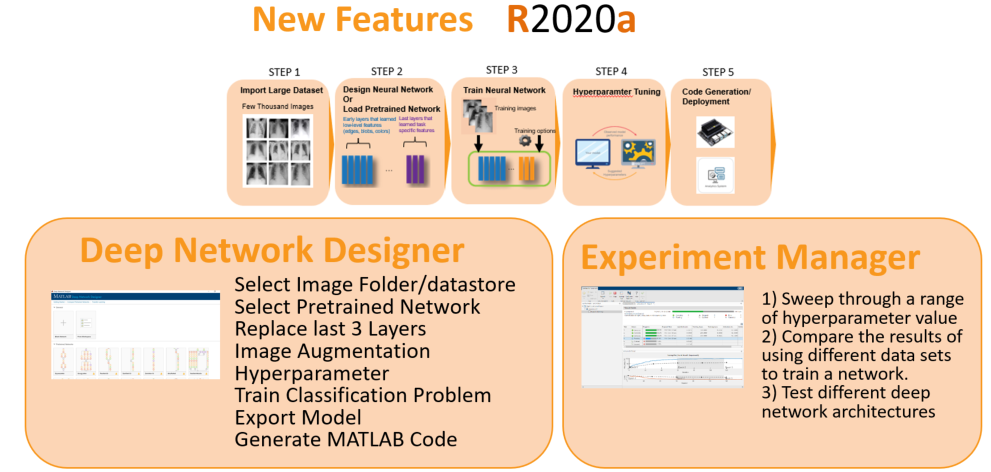

**Written at 24 April 2020**

## **1.0 Use Deep Network Designer to build Deep Learning Model**

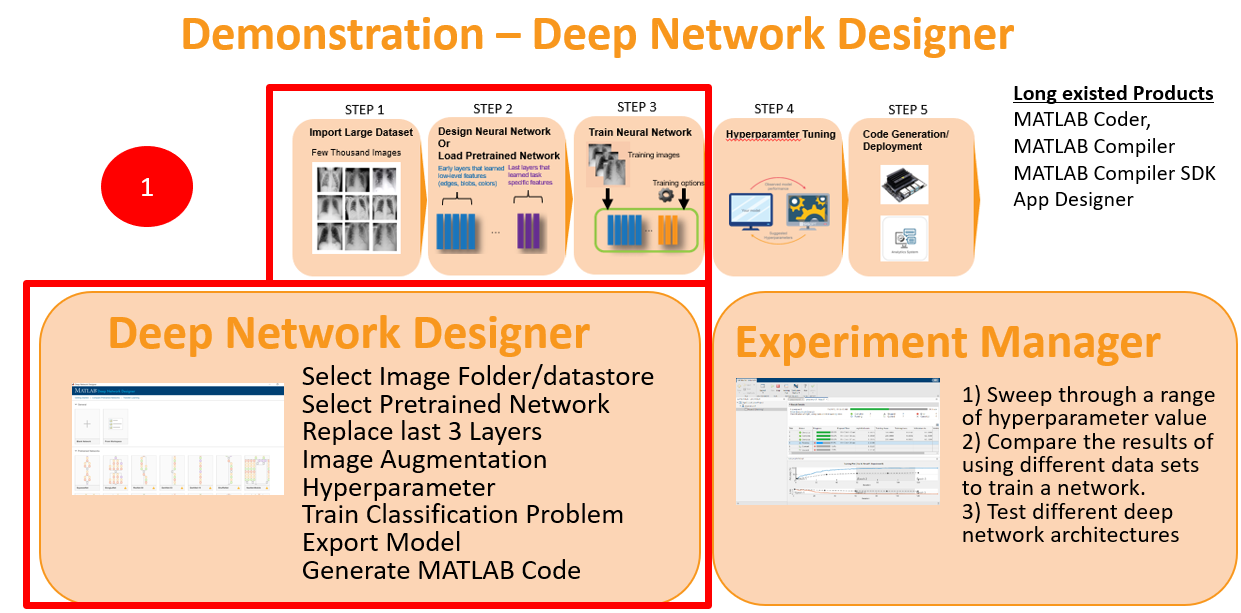

### **1.1 Load Data **

imds = imageDatastore('Data', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
imds.ReadFcn = @customreader; % Standardize all images to 3 channel (RGB)

### 1.2 Open Deep Network Designer

deepNetworkDesigner

### 1.3 Build Model in Deep Network Designer

#### 1.3.1 Select Pretrained Neural Network - Alexnet

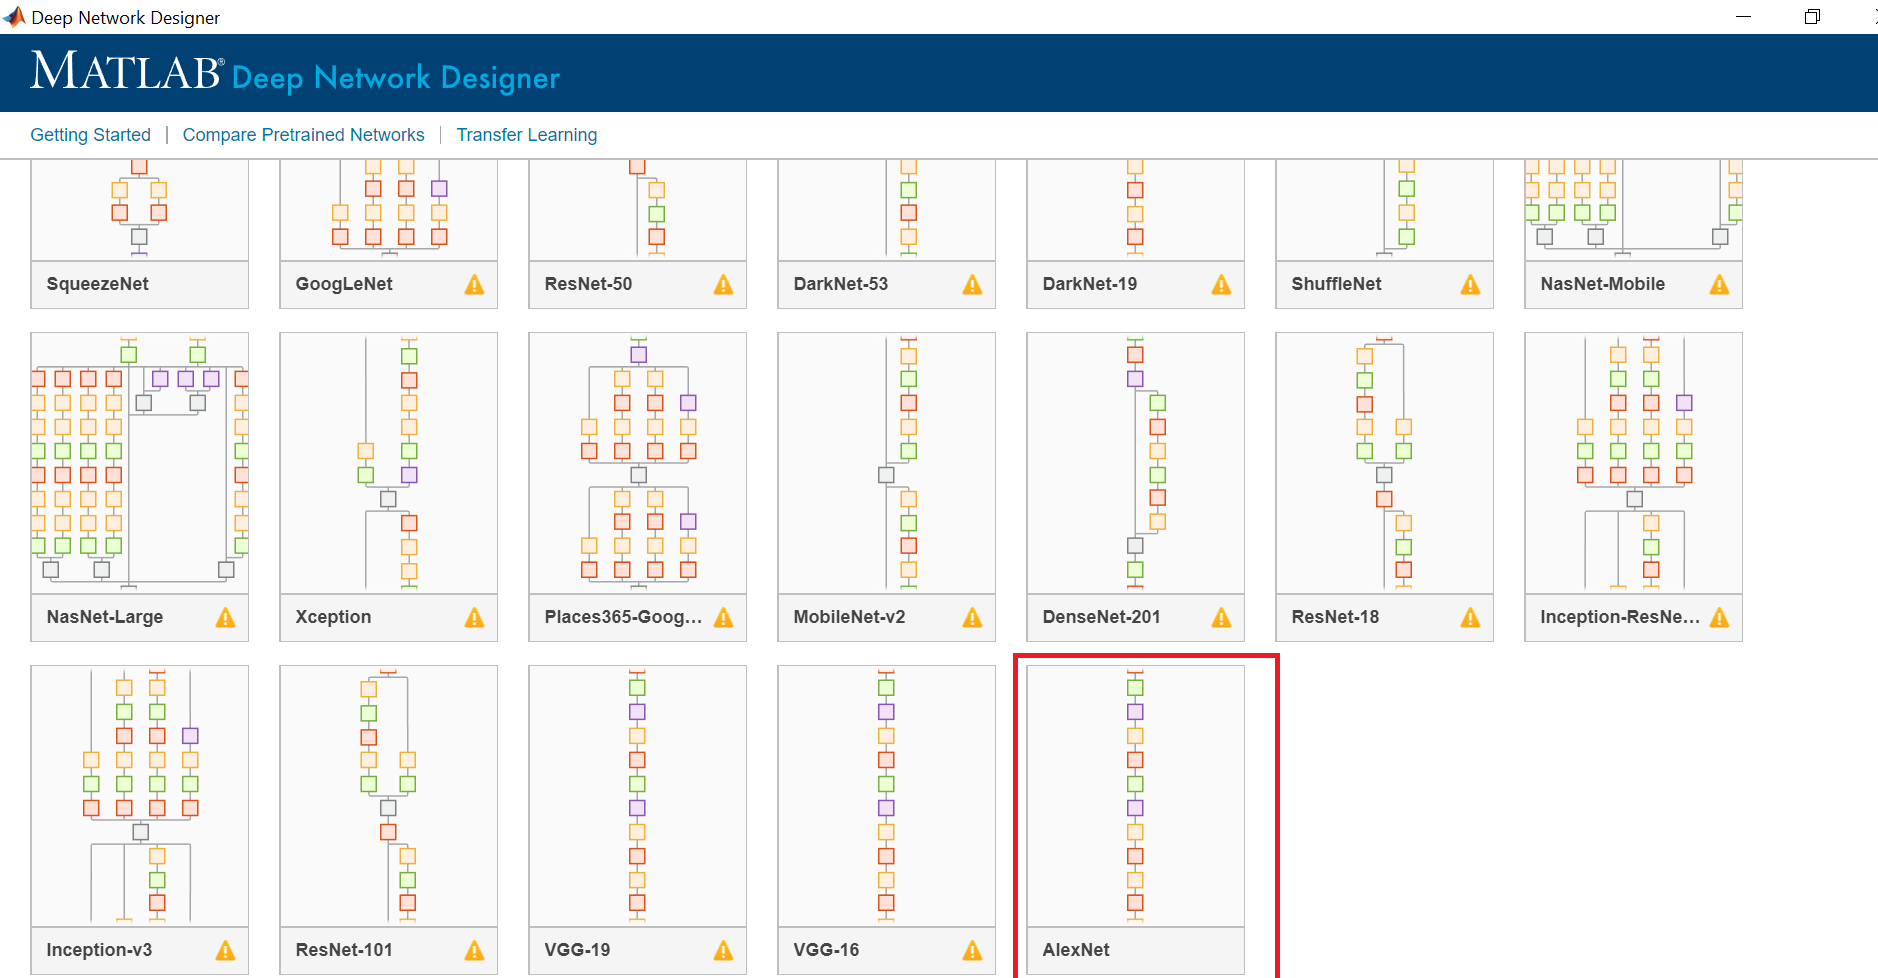

#### 1.3.2 Visualize the architecture/layers of Alexnet

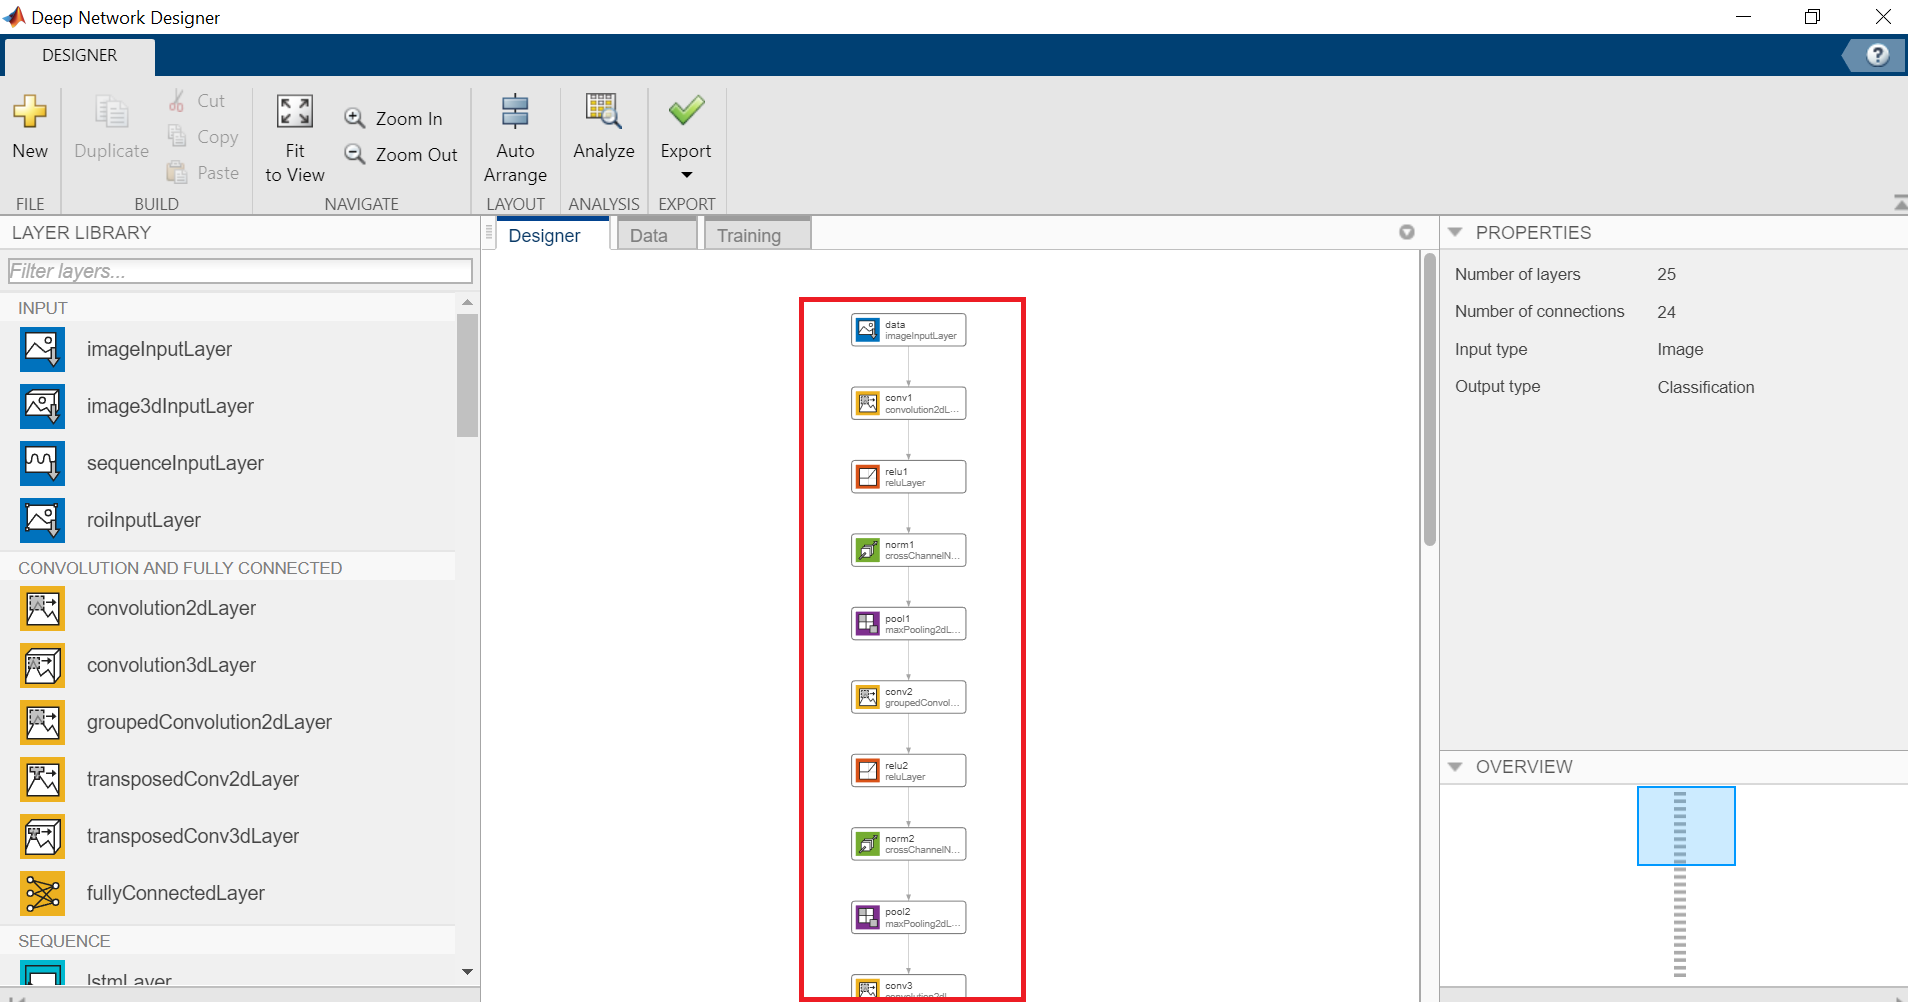

#### 1.3.3 Replace the last 3 layers (Delete the last 3 Layers)

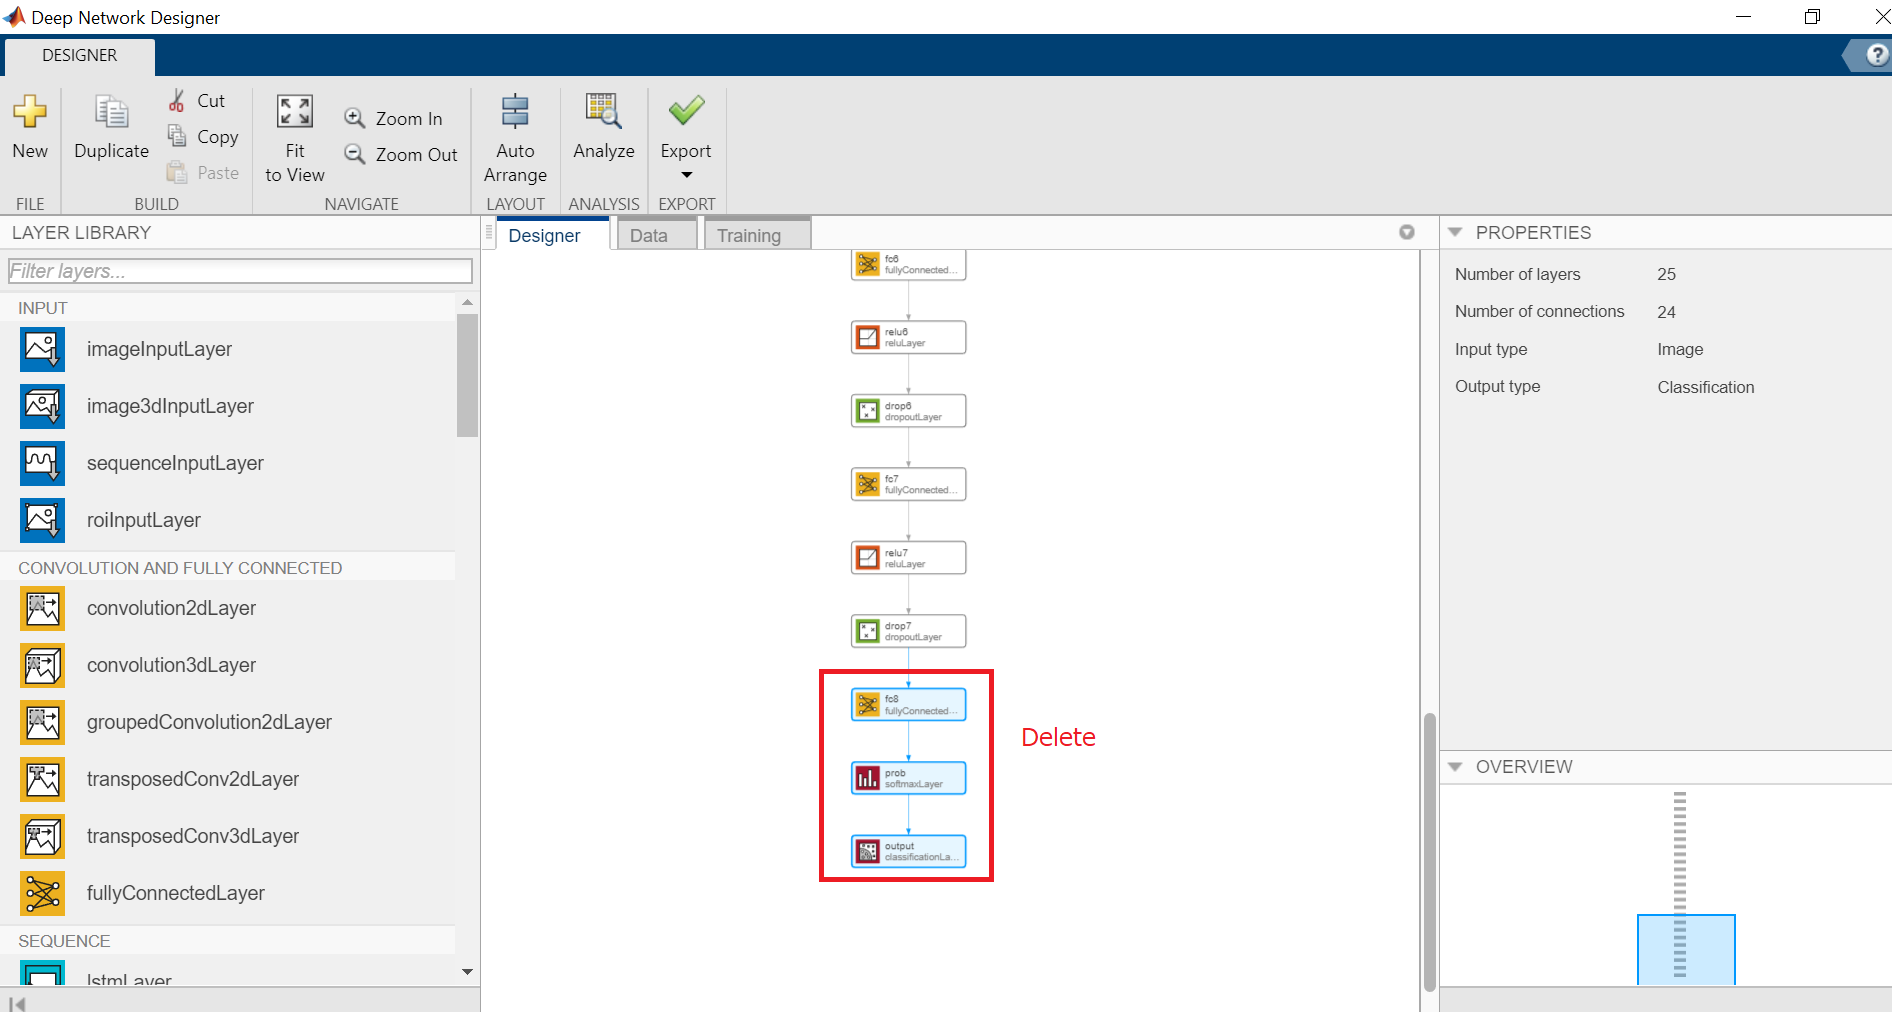

#### 1.3.4 Replace the last 3 layers (Drag and Drop the new last 3 Layers)

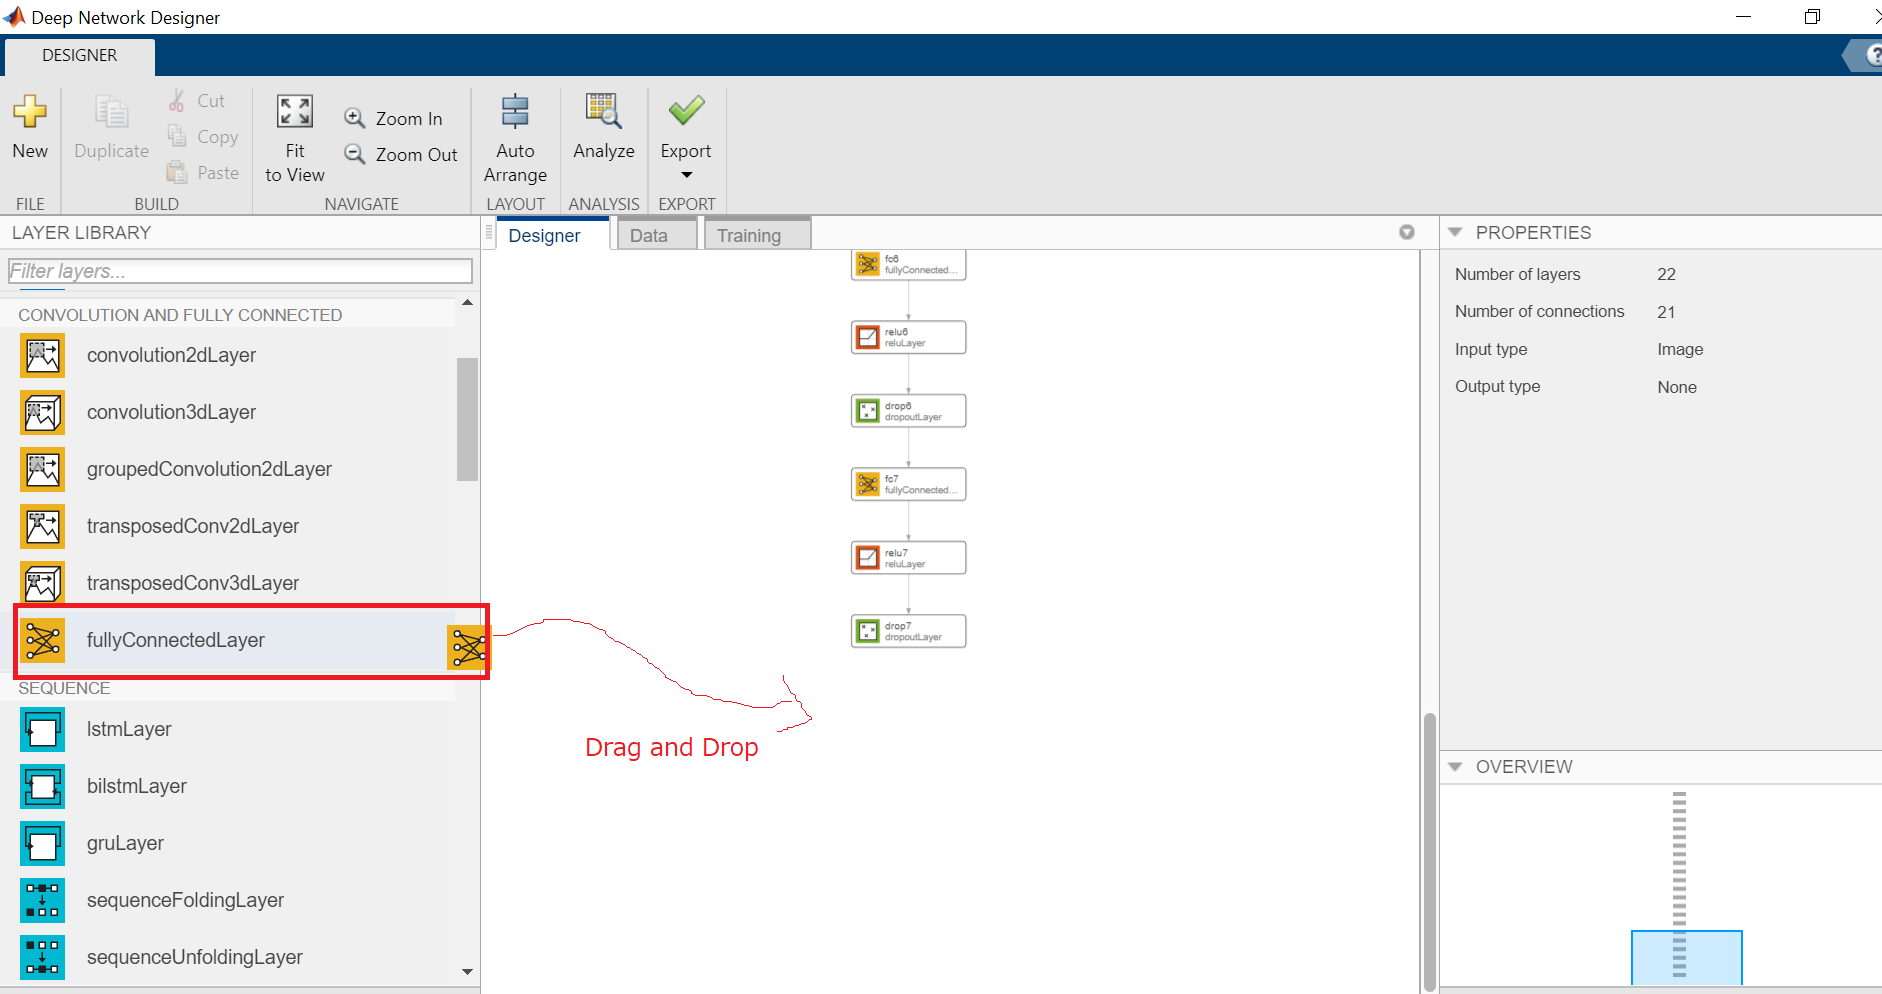

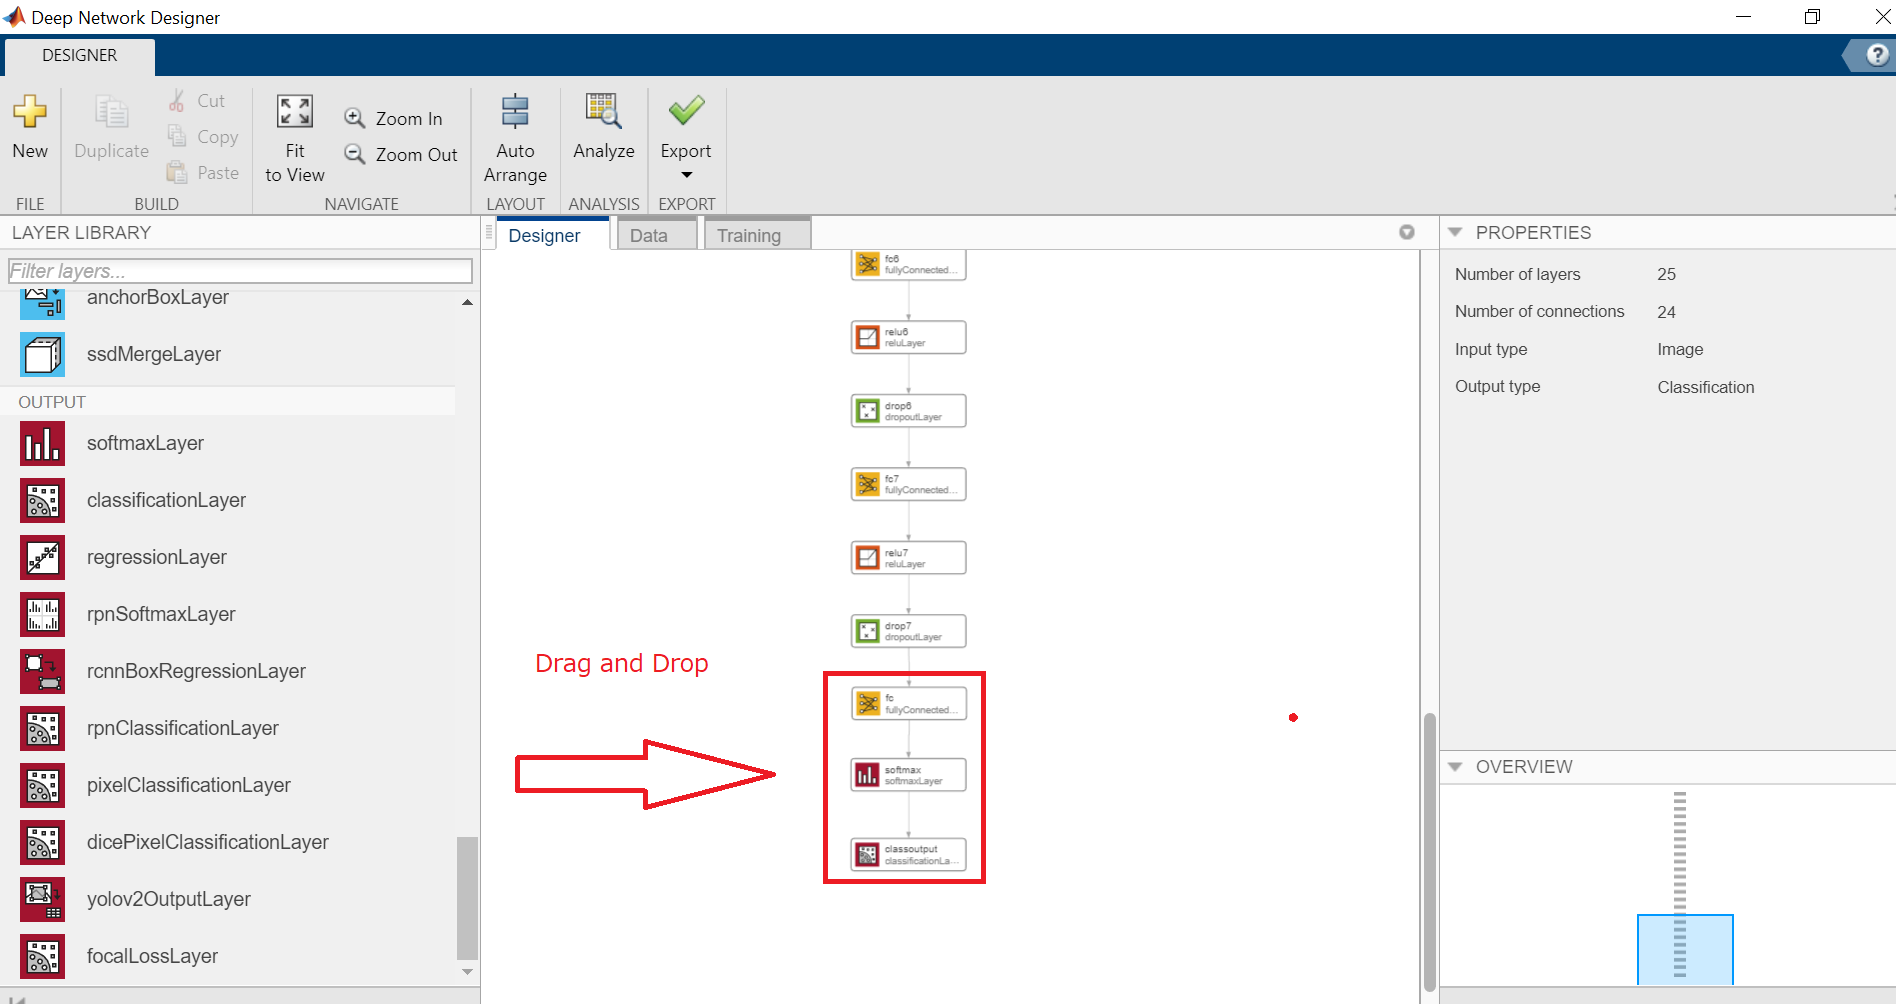

#### 1.3.5 Specify the output size of fully connected layer to 2  (2 Categories - Covid-19 and Normal)

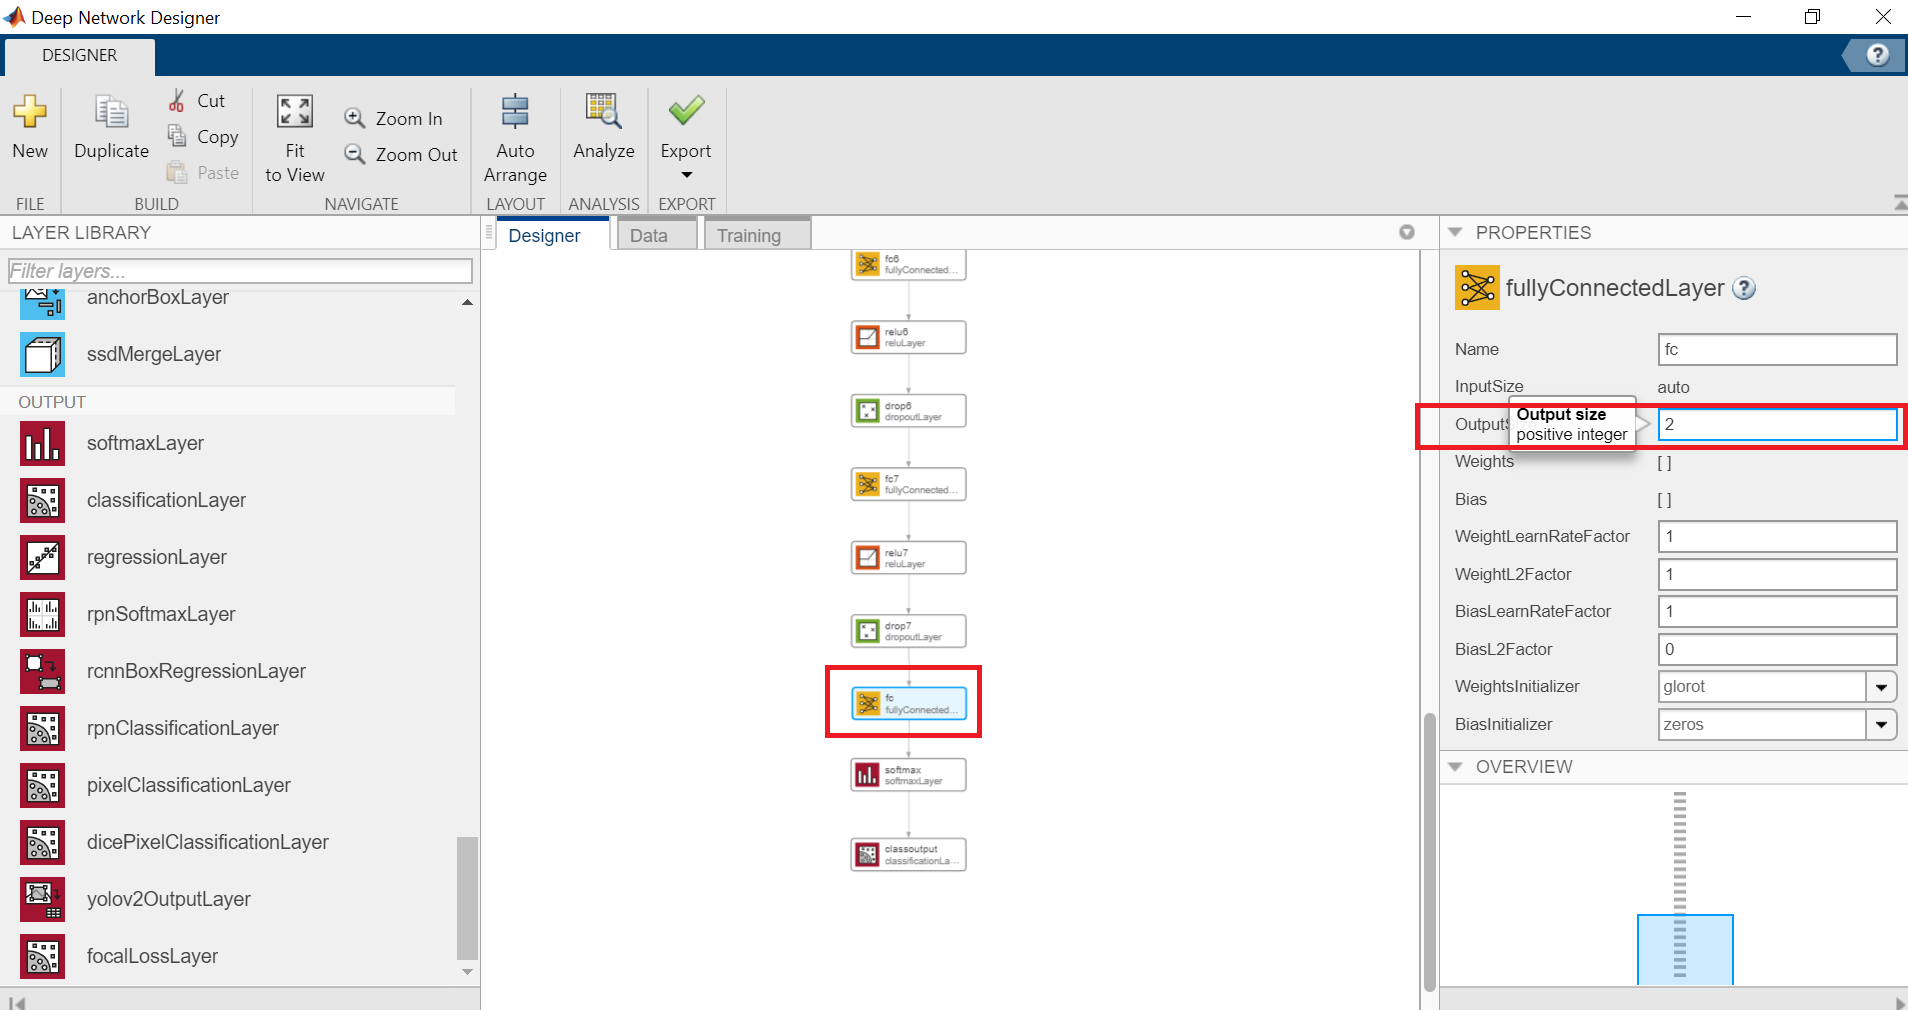

#### 1.3.6 Import Dataset (from imagedatastore)

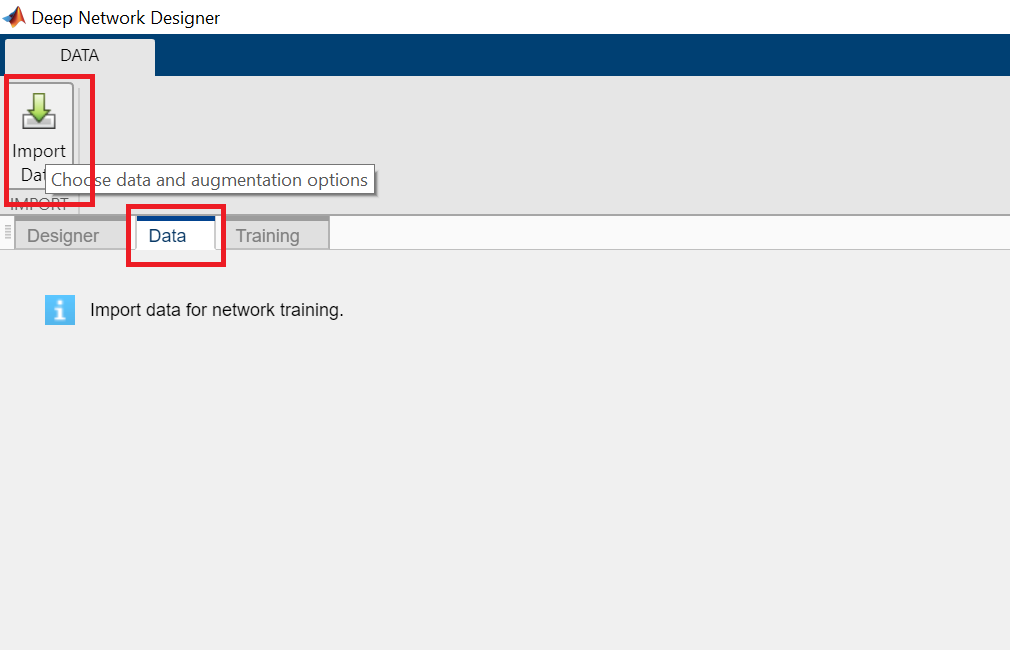

#### 1.3.7 Import Dataset (from imagedatastore)

import data from imagedatastore (workspace)

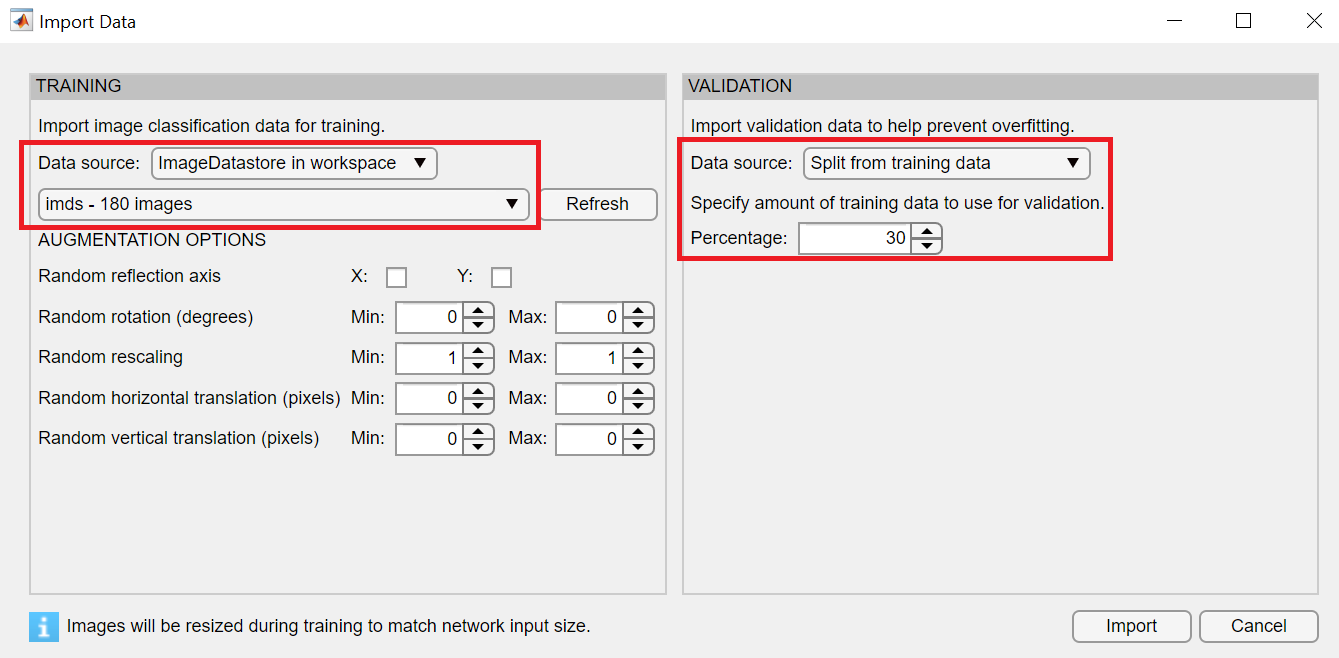

#### 1.3.8 Visualize the imported data

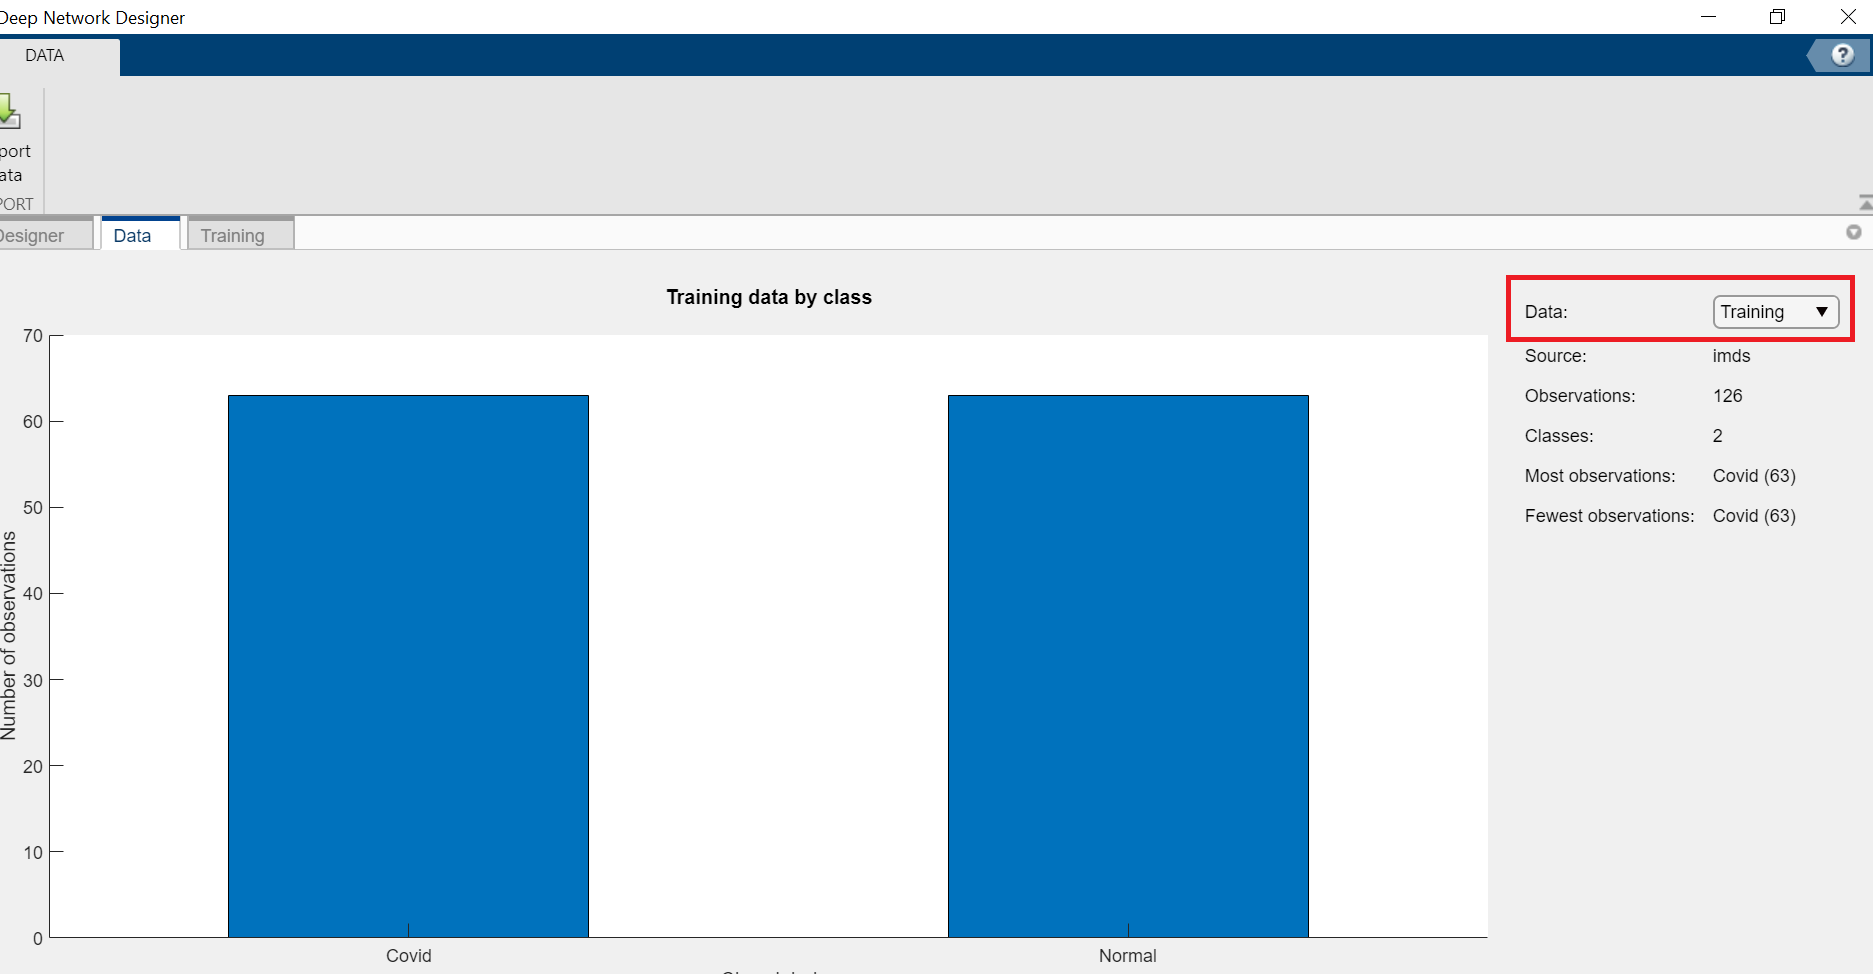

#### 1.3.9 Change to Training Tab

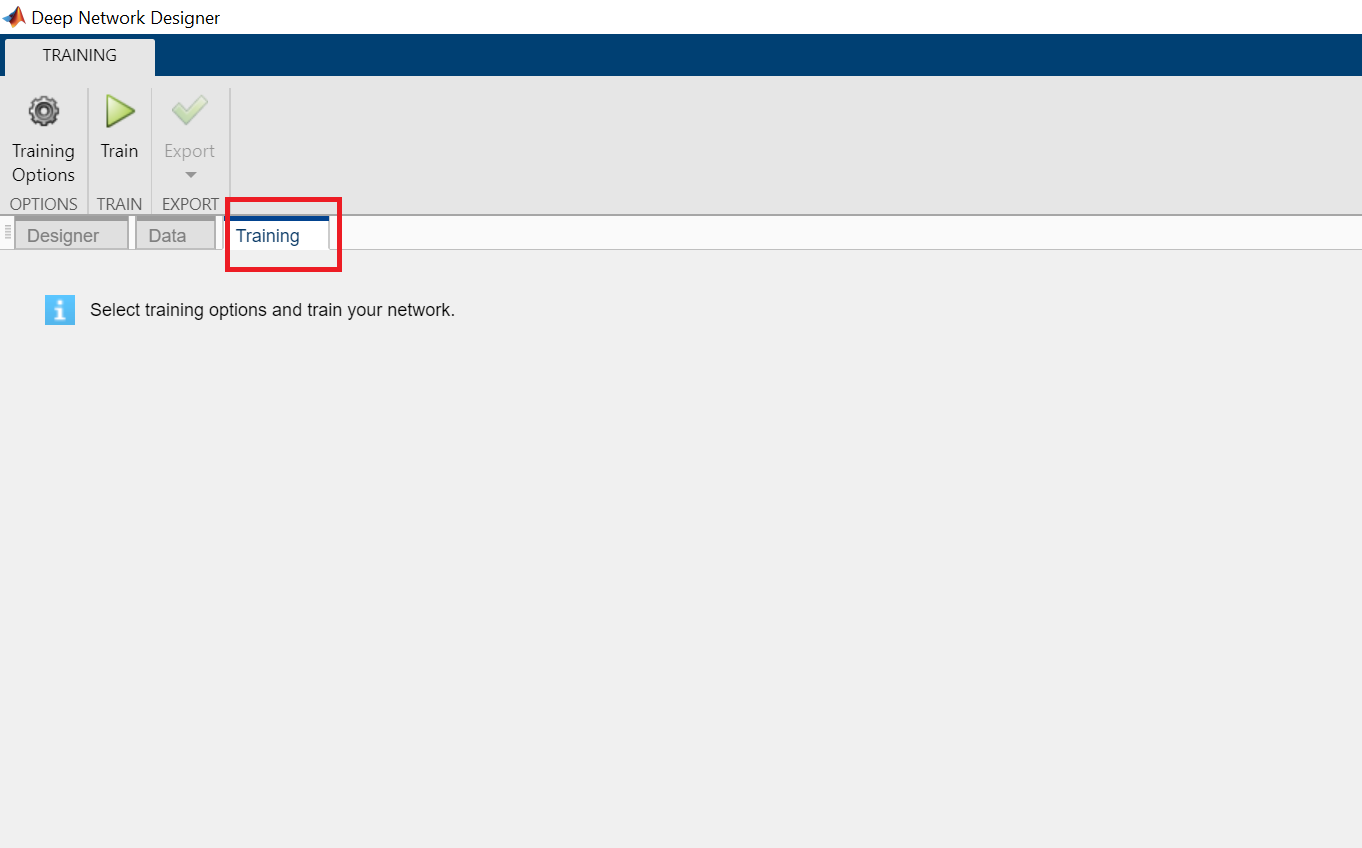

#### 1.3.10 Specify the Training Options 

- Initial Learn Rate change to 0.0001

- Validation Frequency change to 3

- Max Epochs change to 6

- Mini Batch Size change to 10

- Execution Environment change to GPU (If your PC dont have gpu, then you can use CPU)

- Validation Patience change to 3

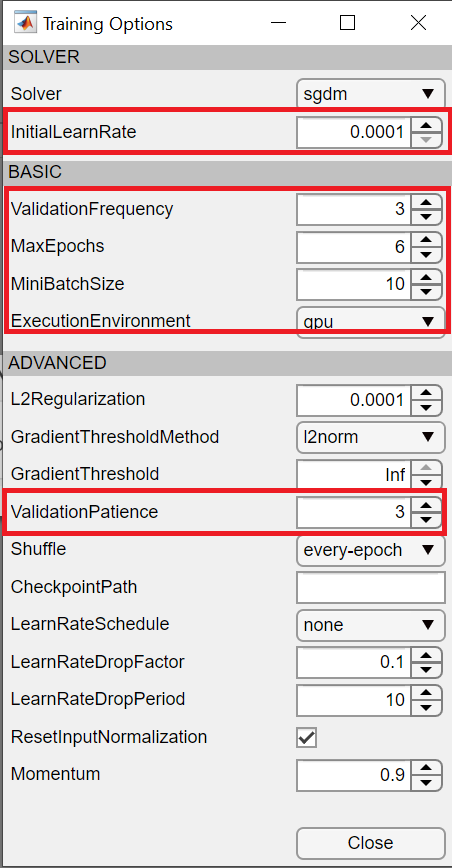

#### 1.3.11 Train the Model

 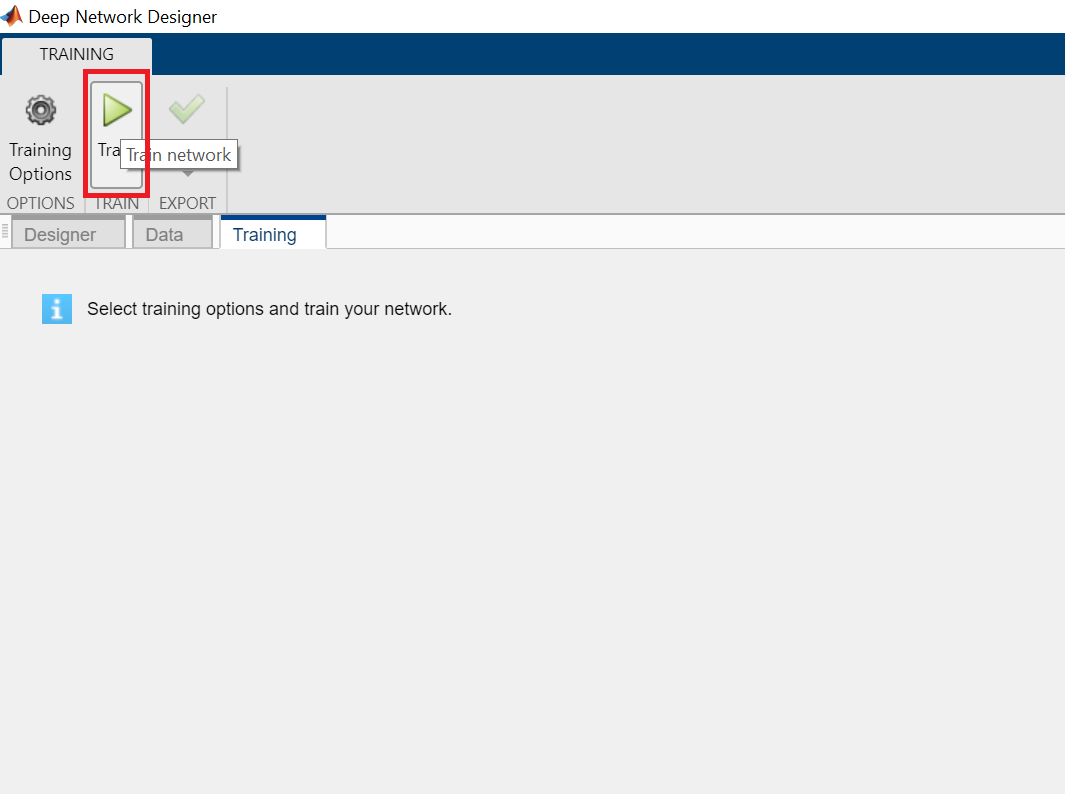

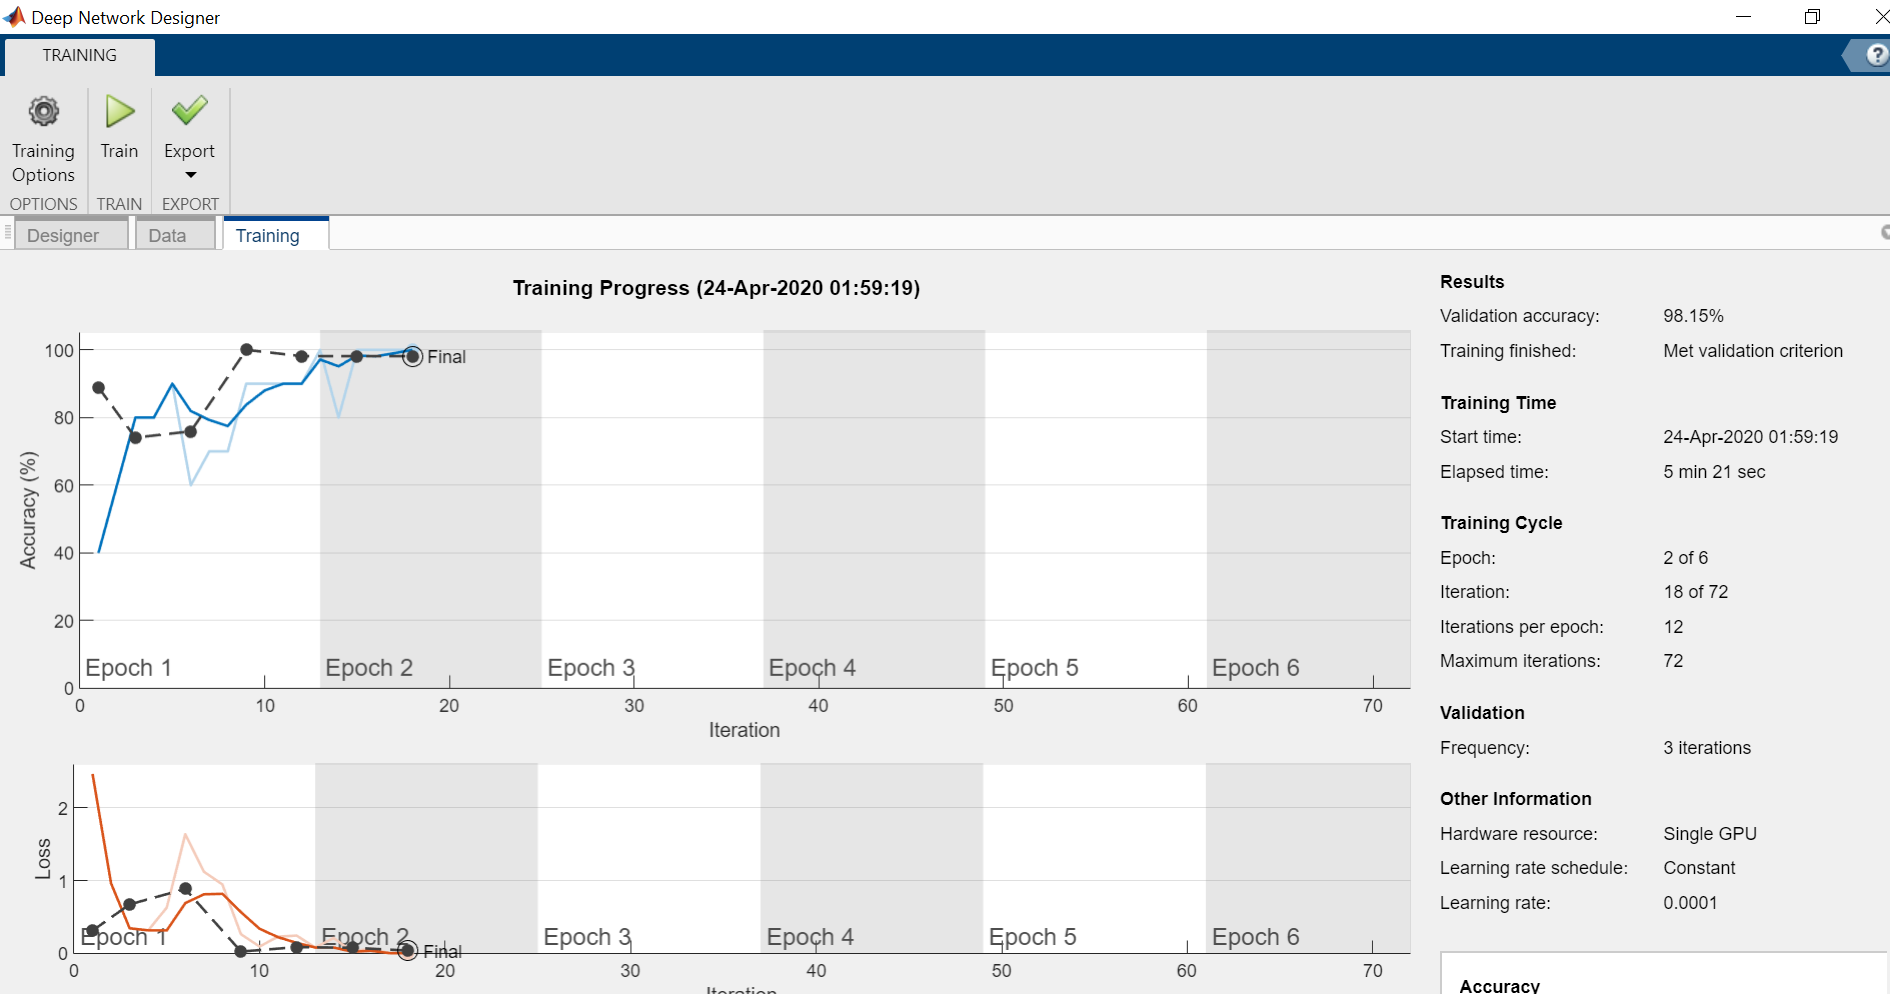

#### 1.3.11 Export Trained Model to Workspace

(Do not close the Deep Network Designer, we will come back to the app later)

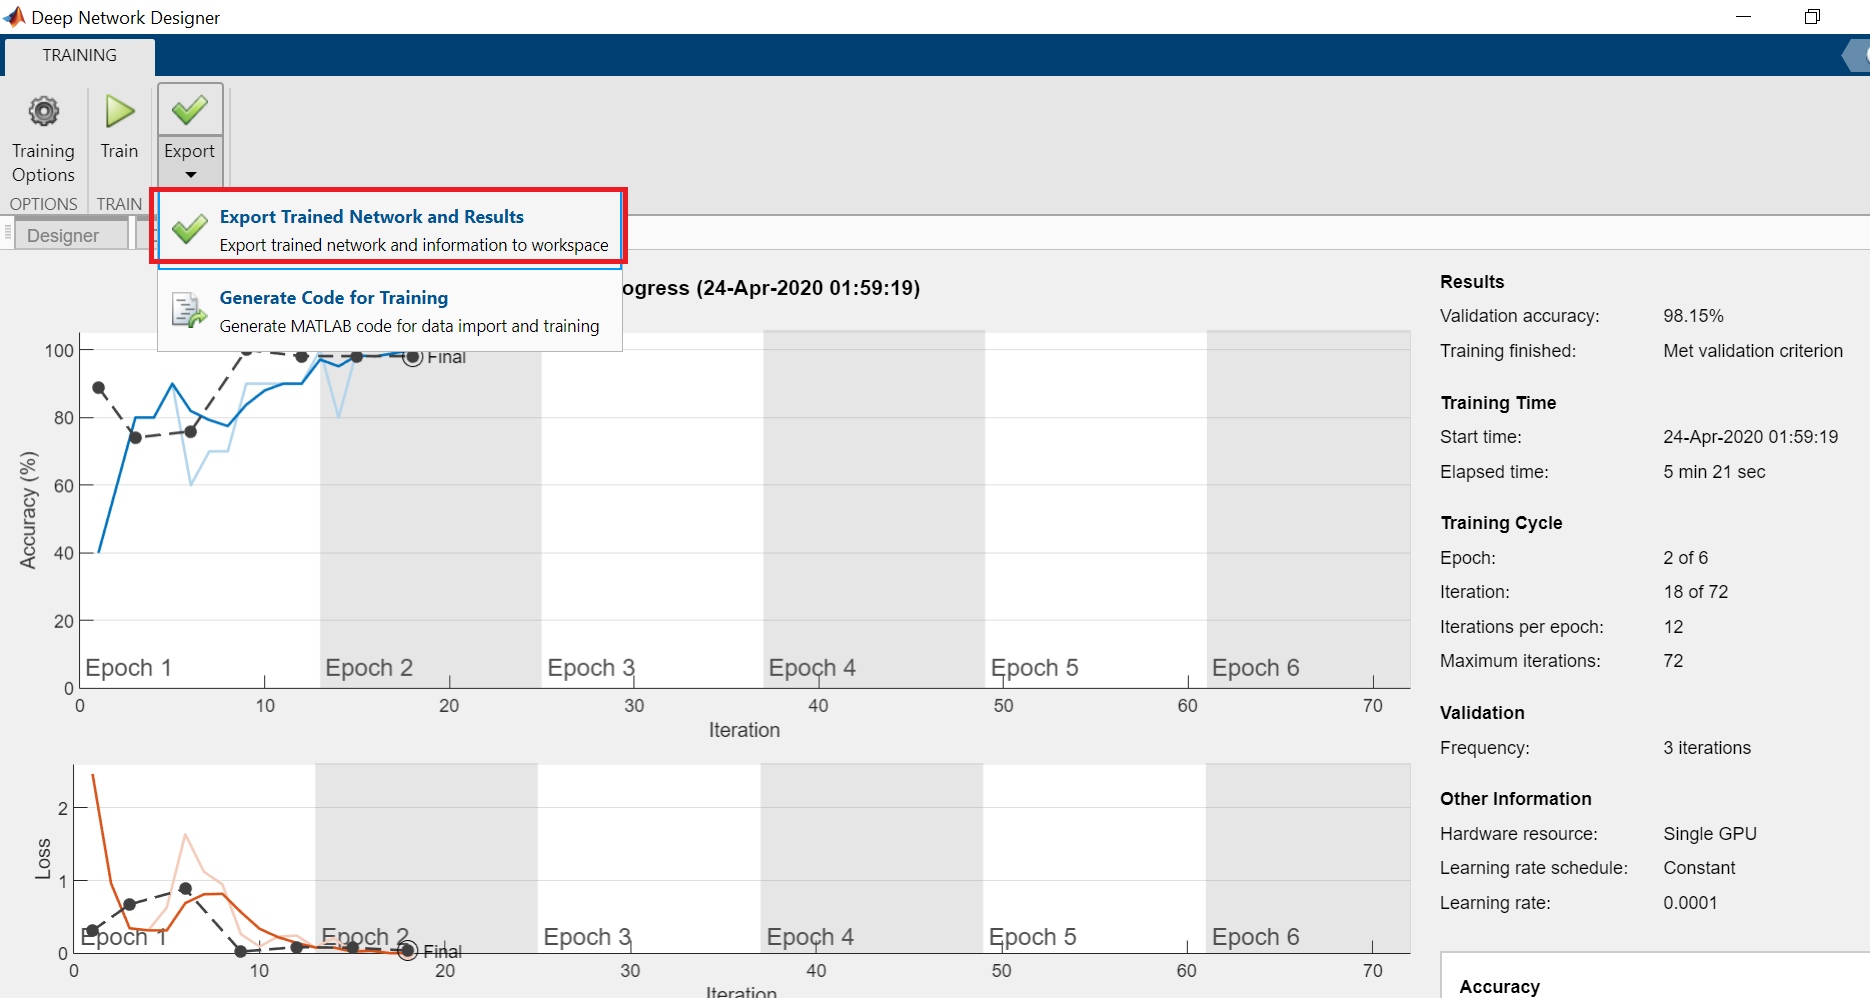

#### 1.3.12 Classify New Image using the Trained Model

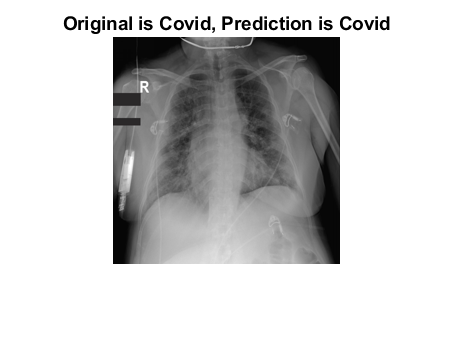

idx = randperm(numel(imds.Files),1);
X = imread(imds.Files{idx});
if size(X,3) == 1
     X = cat(3, X, X, X);     
end
X = imresize(X,[227 227]);
[YPred,scores] = classify(trainedNetwork_1,X);
imshow(X)
title(sprintf("Original is %s, Prediction is %s",string(imds.Labels(idx)),string(YPred)));

#### 1.3.12 Generate Code for Training

keep the generated script aside, do not close it.

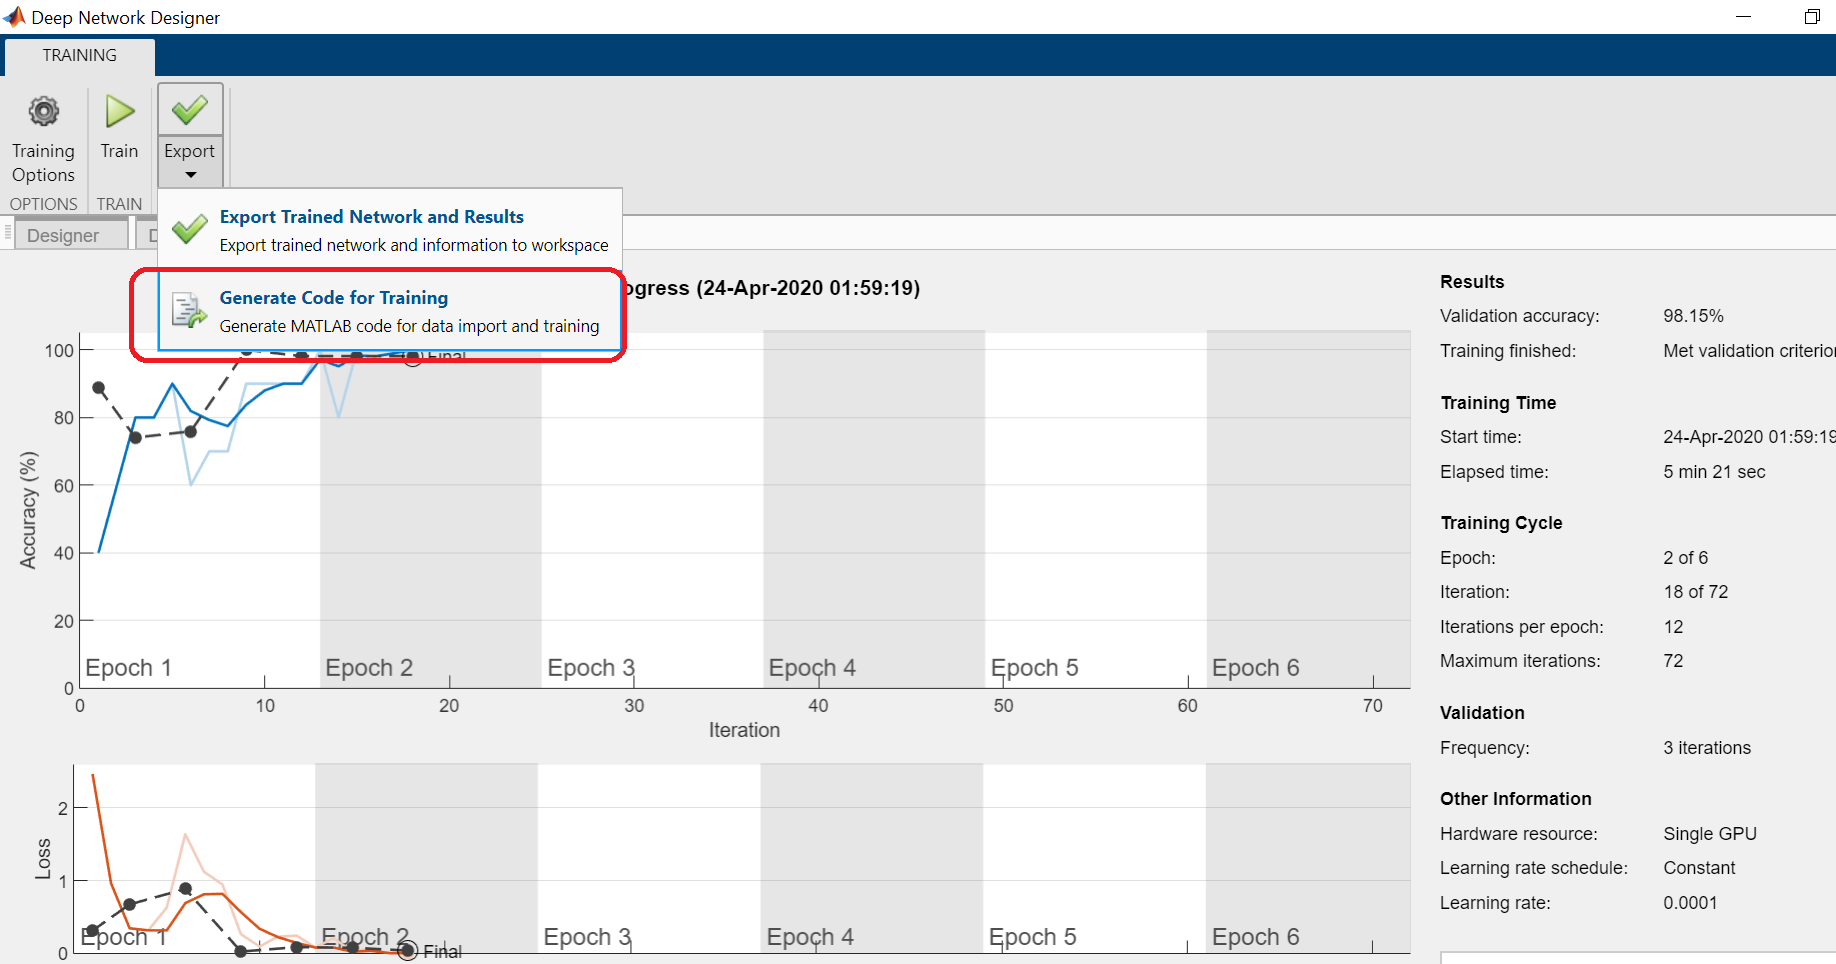

## **2.0 Use Experiment Manager to try different hyperamater value/pretrained neural network/dataset/etc**

- In this exam, we are going to try different learning rate and see which one has the higher accuracy.

experimentManager

### 2.1 Create New Project

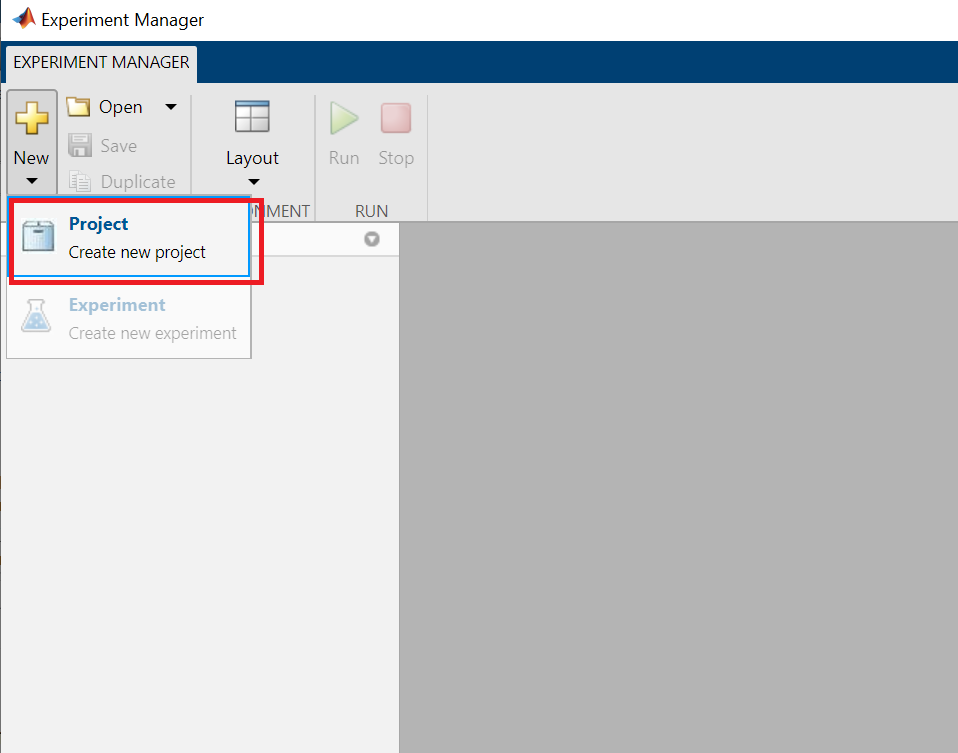

### 2.2 Write description and specify the value of hyperparameter

you can write any description yourself, specify the myInitialLearnRate : [1e-3,1e-4]

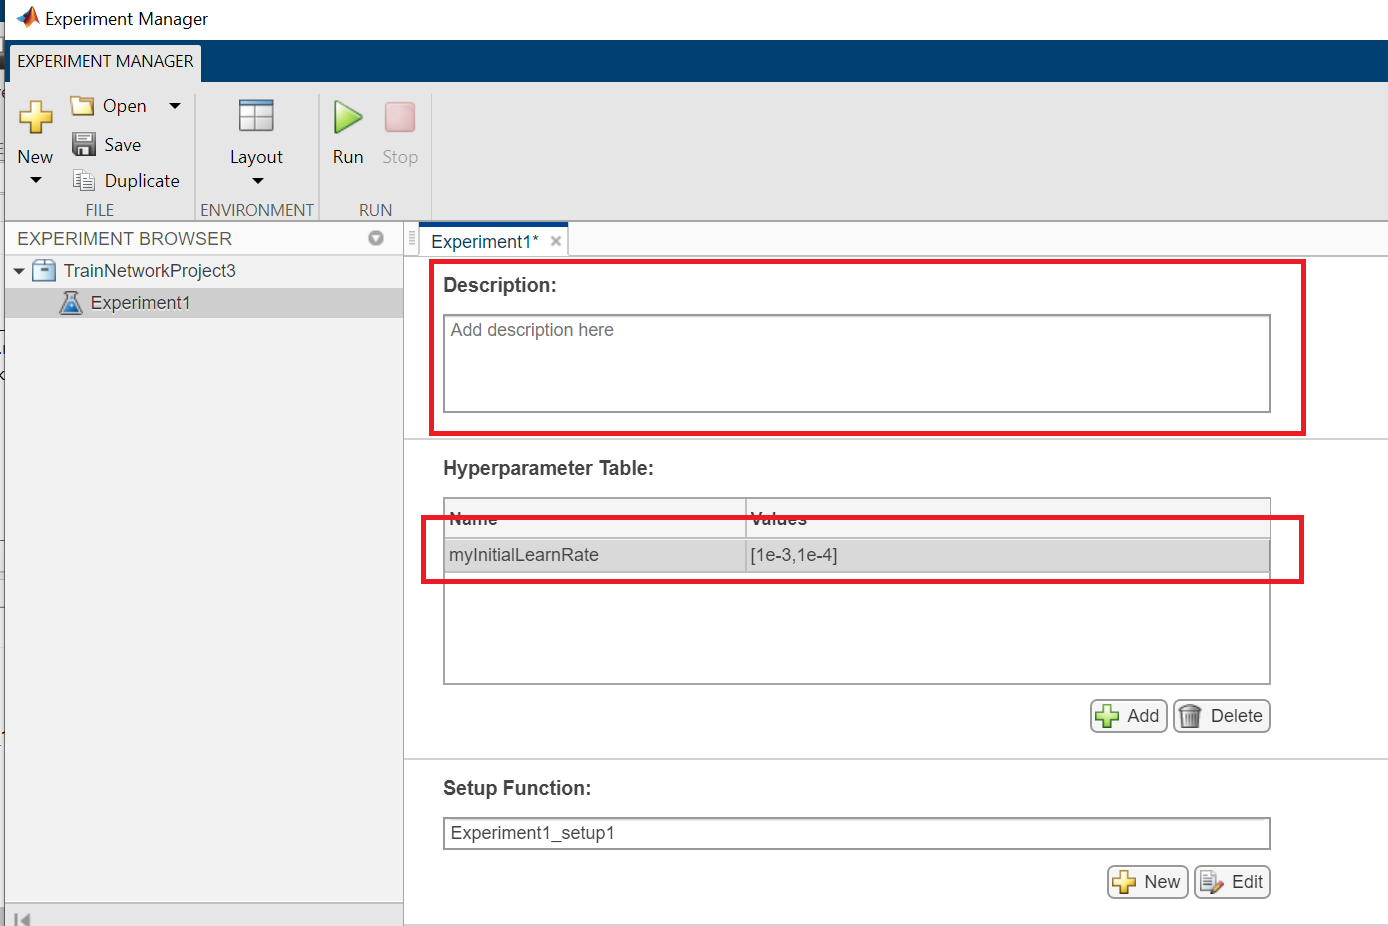

### 2.3 Modify the Setup Function

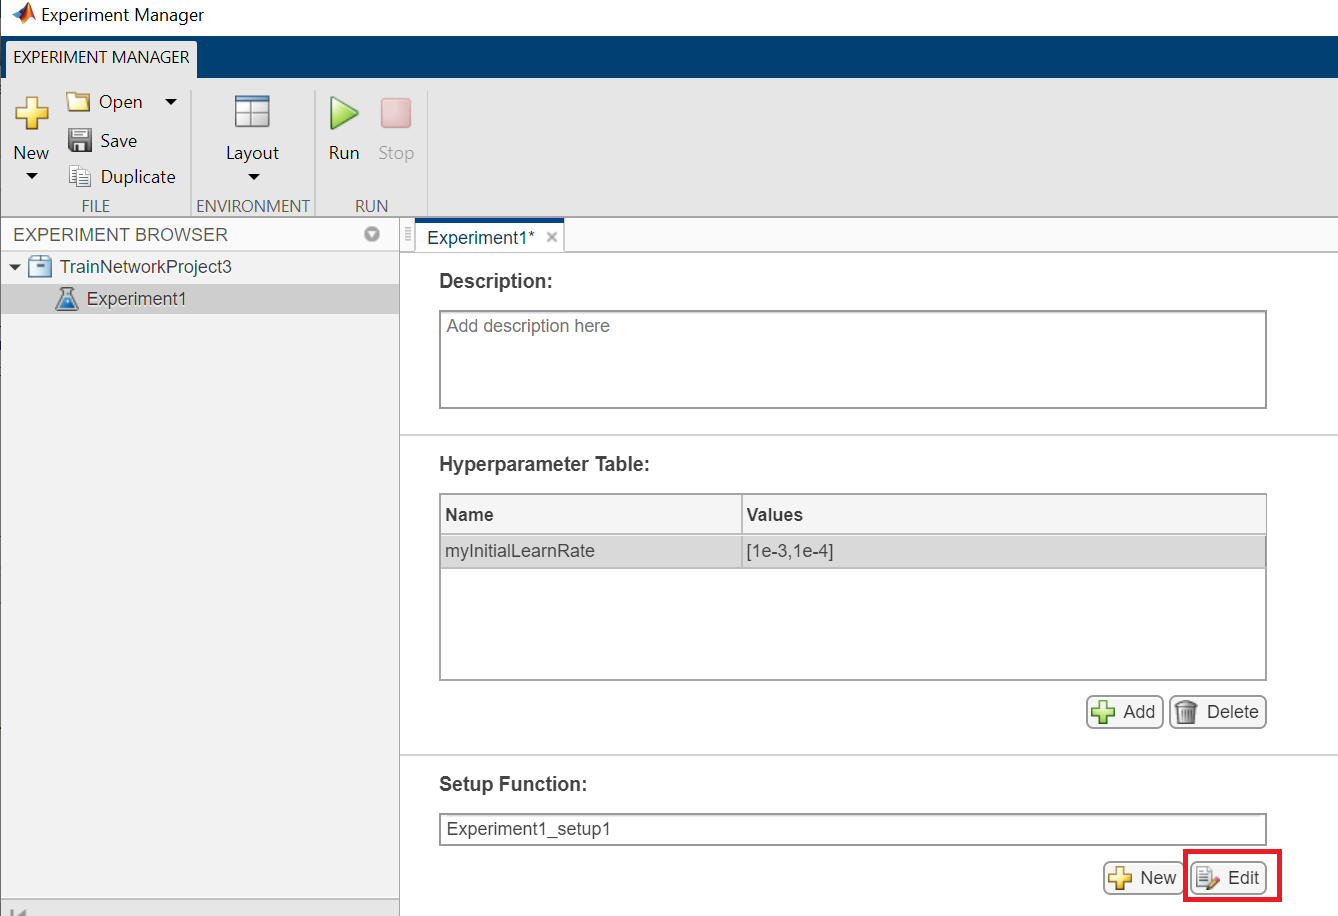

#### 2.3.1 Copy Code from generated script (from Deep Network Designer) and paste on Setup Function

- Delete all the code inside the function of Setup Function script.

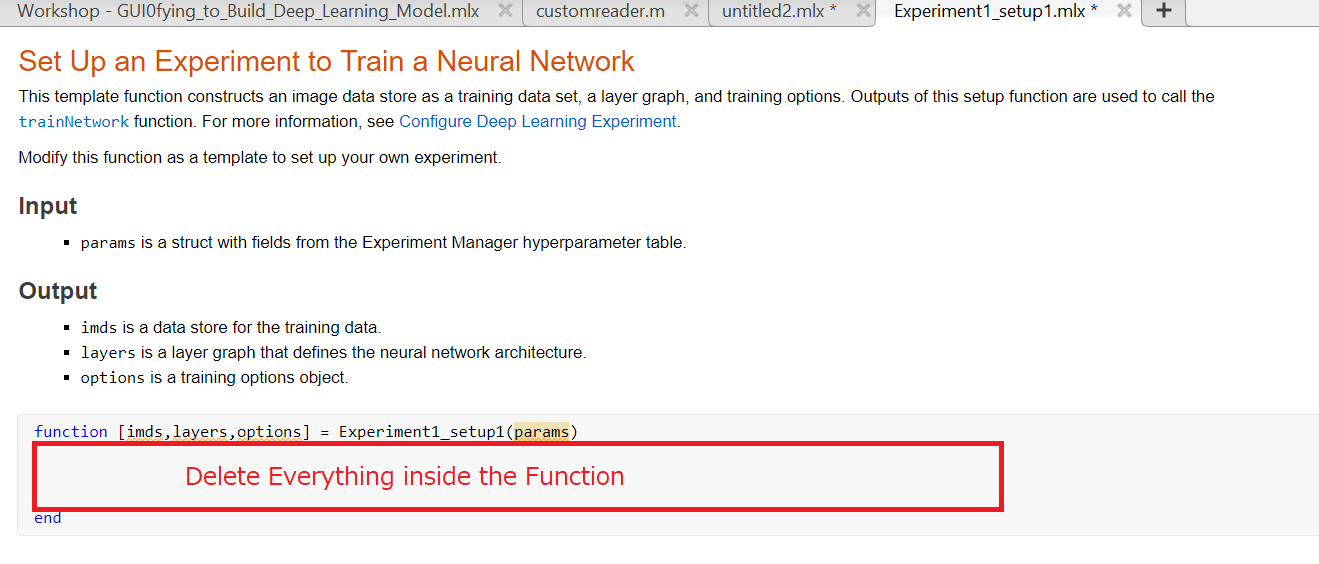

- Copy all the code from genetrated script from Deep Network Designer, ***except ***trainNetwork (last line in the script)

- Past them insde the function of Setup Function Script

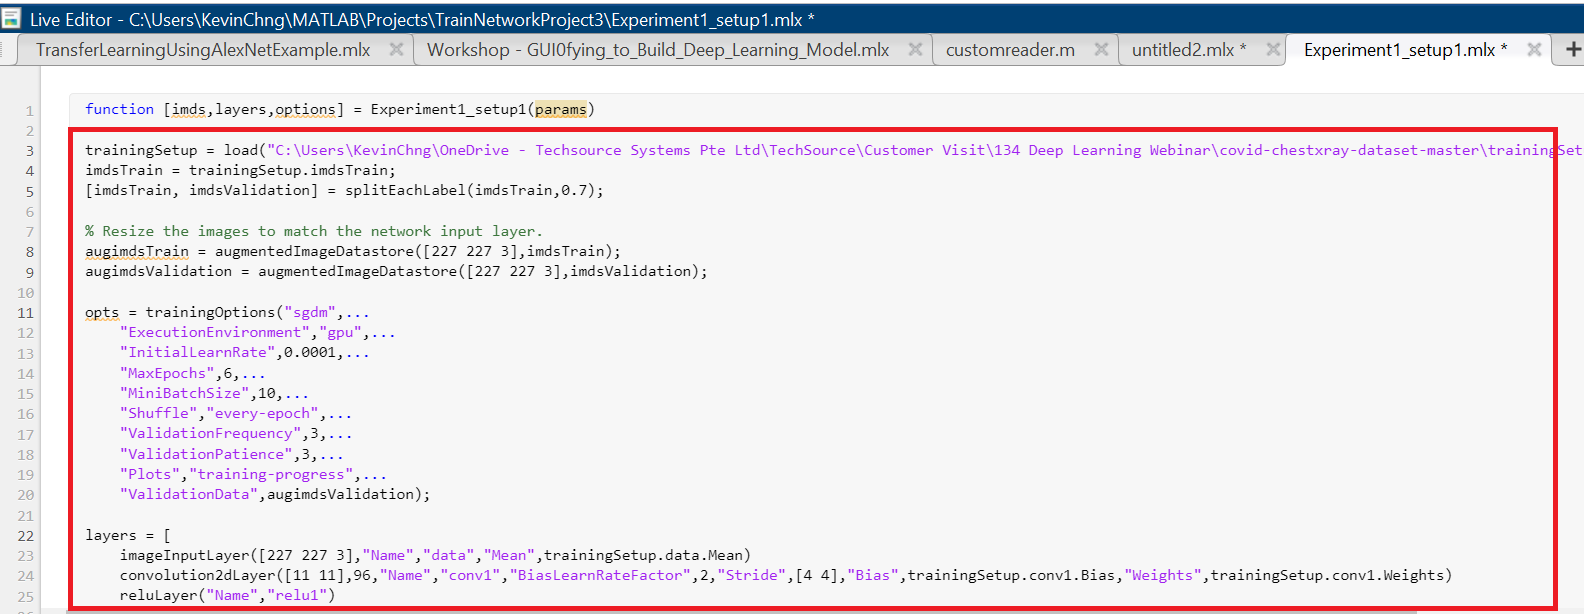

- Change the name of output in the function of Setup Function Script

- For this example, we change to [augImdsTrain,layers, opts]

- If you look at detail, then you will discover that the 3 outputs here are the 3 inputs for trainNetwork function in the generated script of Deep Network Designer

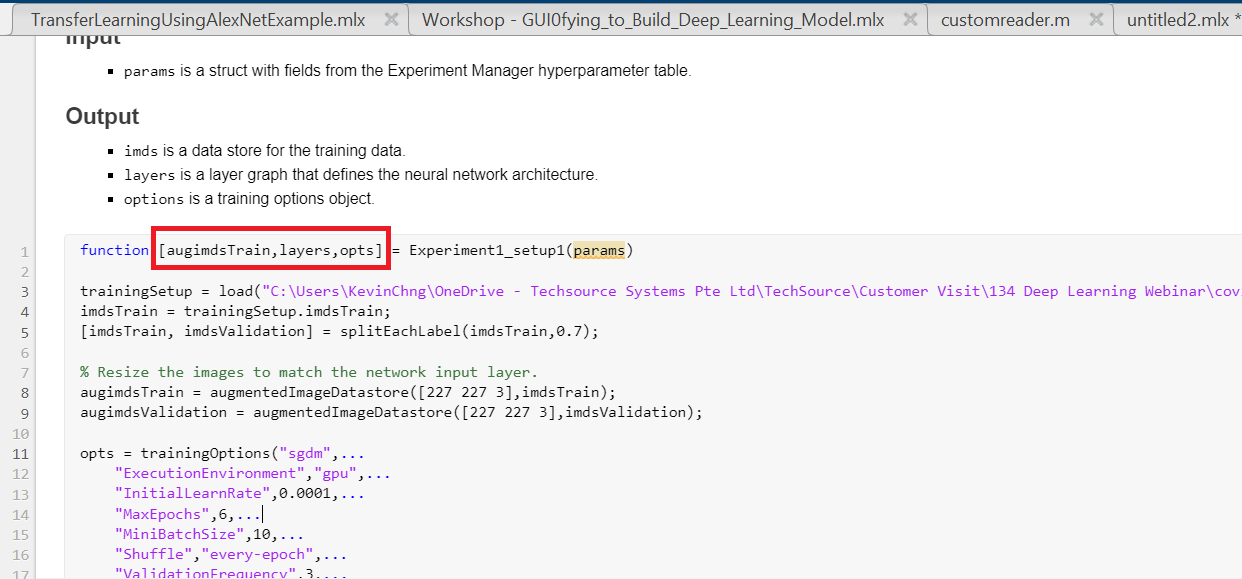

- Save the script

### 2.4 Run Experiment Manager

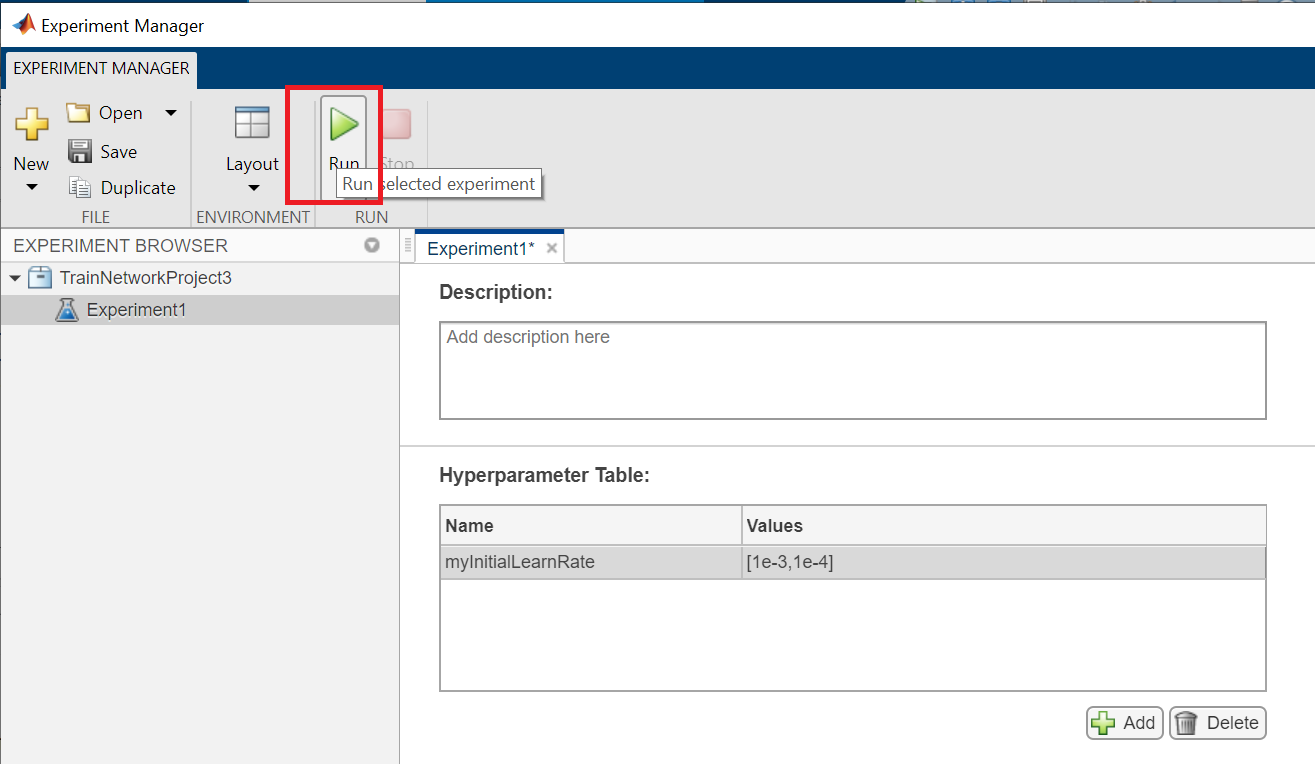

### 2.4 Visualize the result

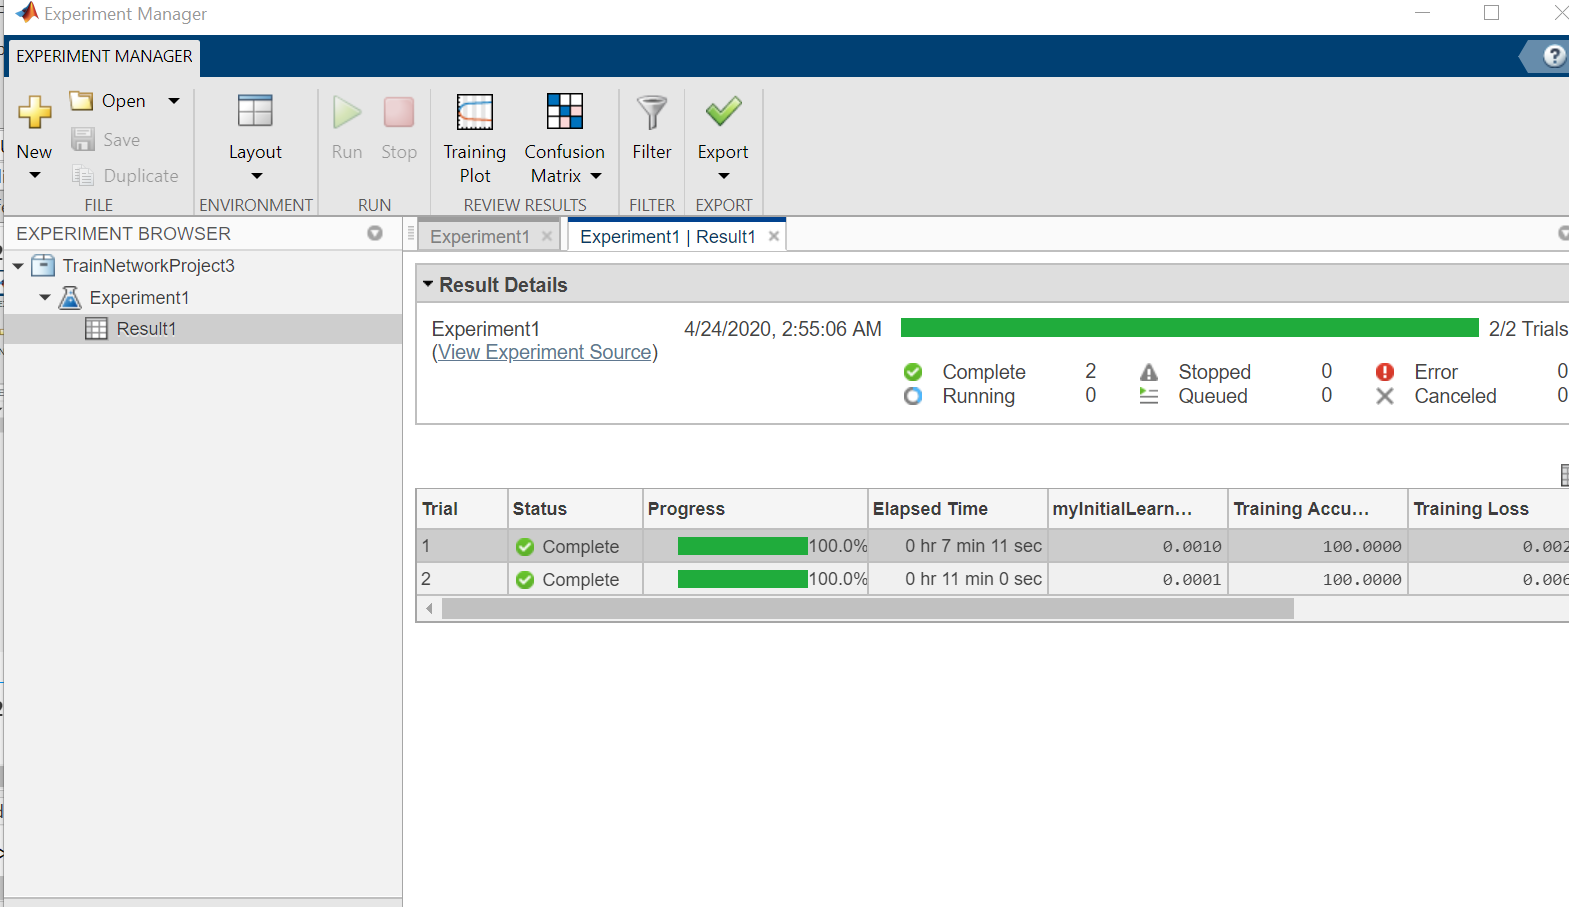

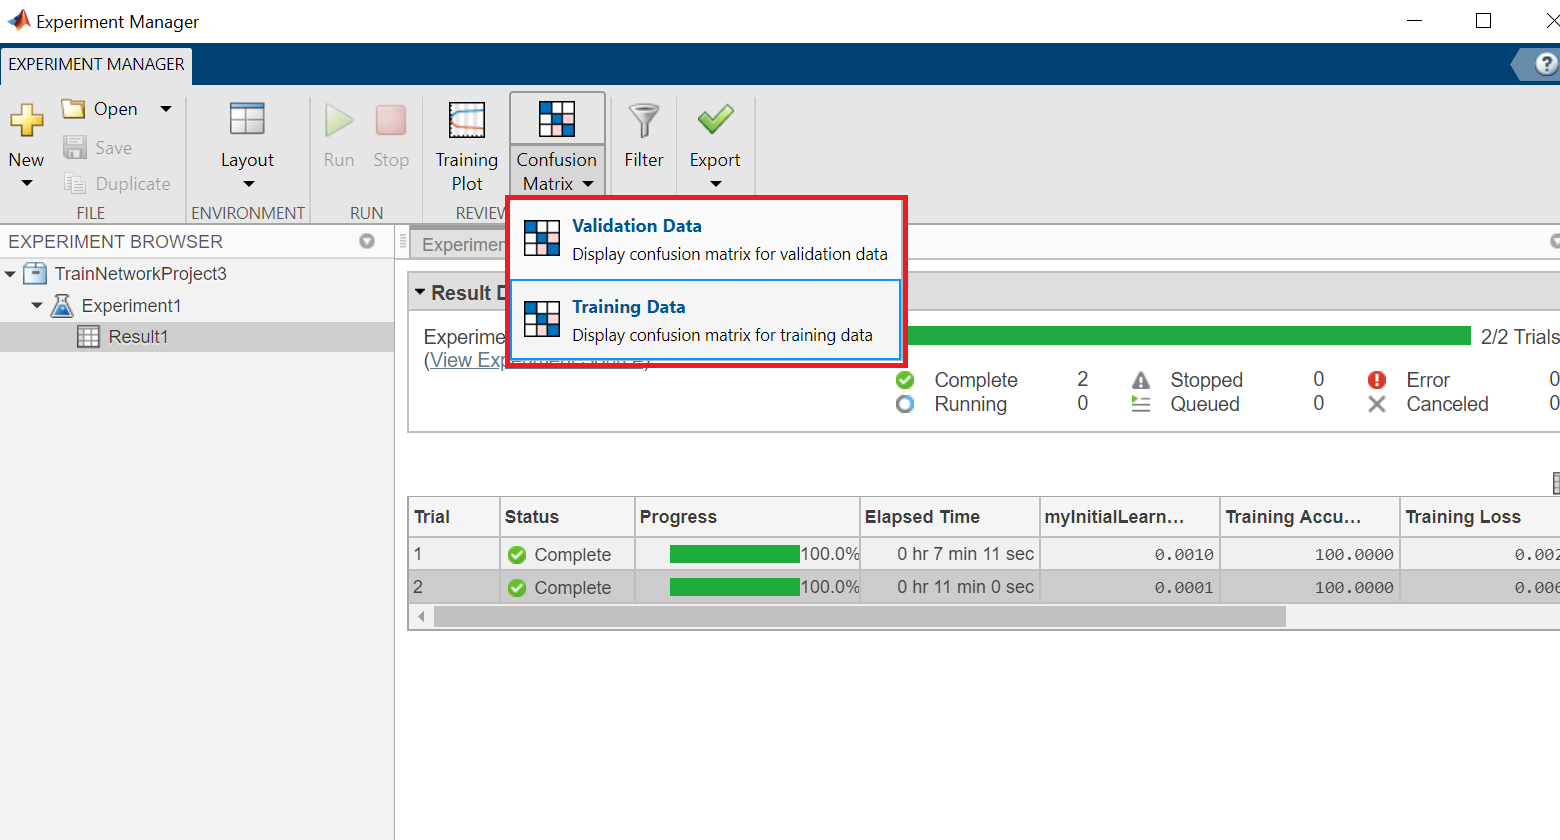

### 2.5 Export the Best Network

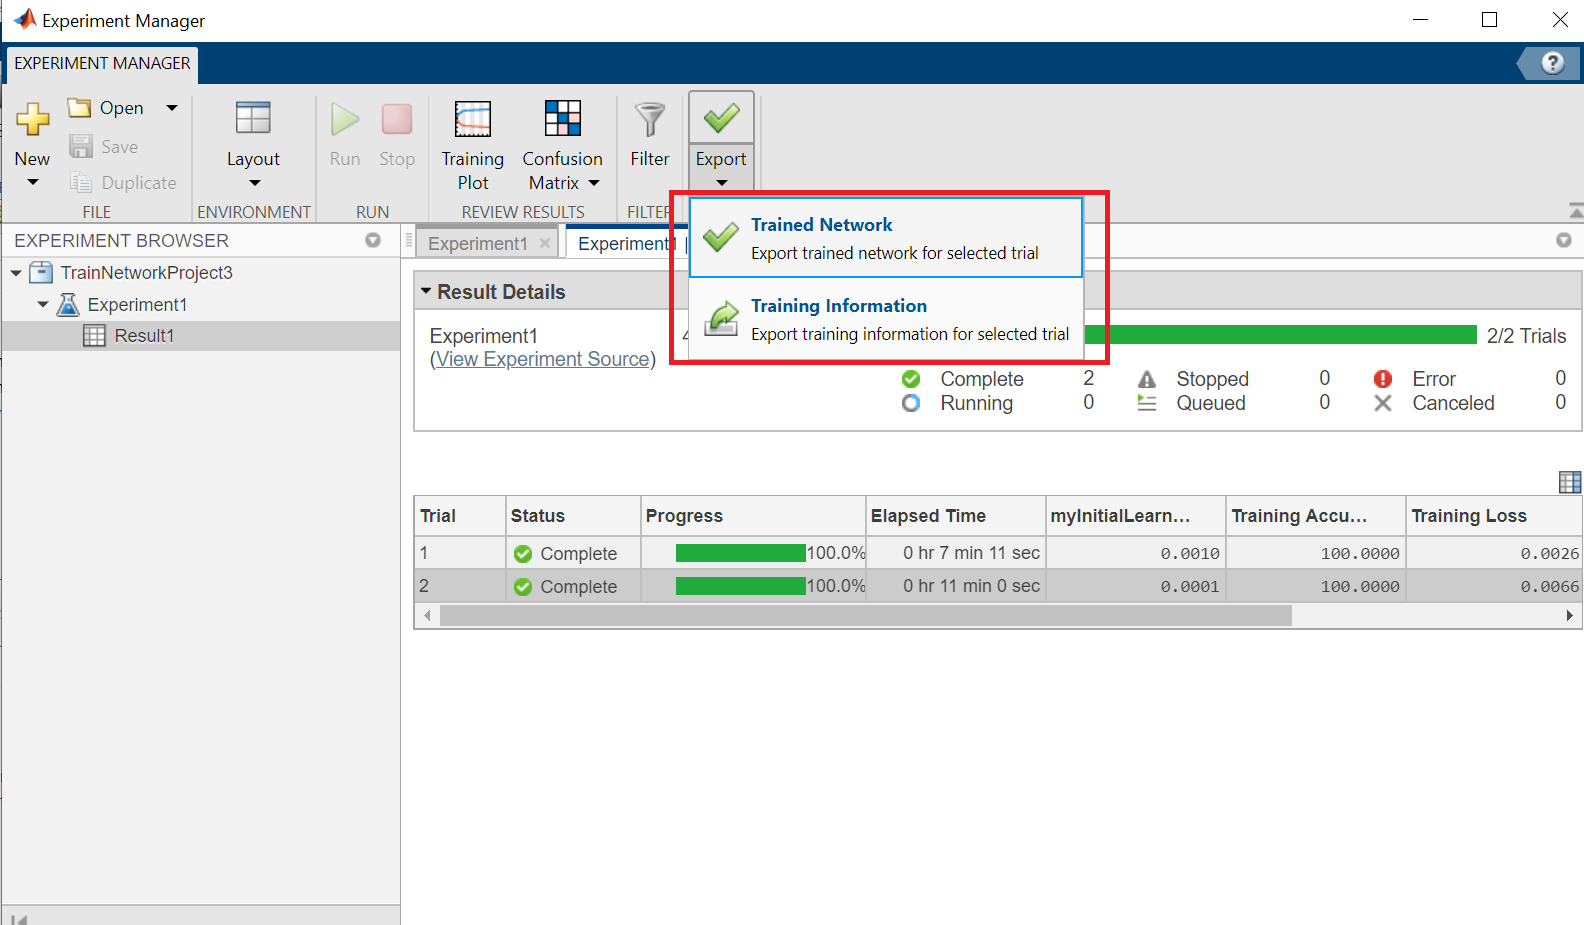

## End

For deployment option, you may refer to article below:

[https://www.mathworks.com/company/newsletters/articles/selecting-a-matlab-application-deployment-strategy.html](https://www.mathworks.com/company/newsletters/articles/selecting-a-matlab-application-deployment-strategy.html)